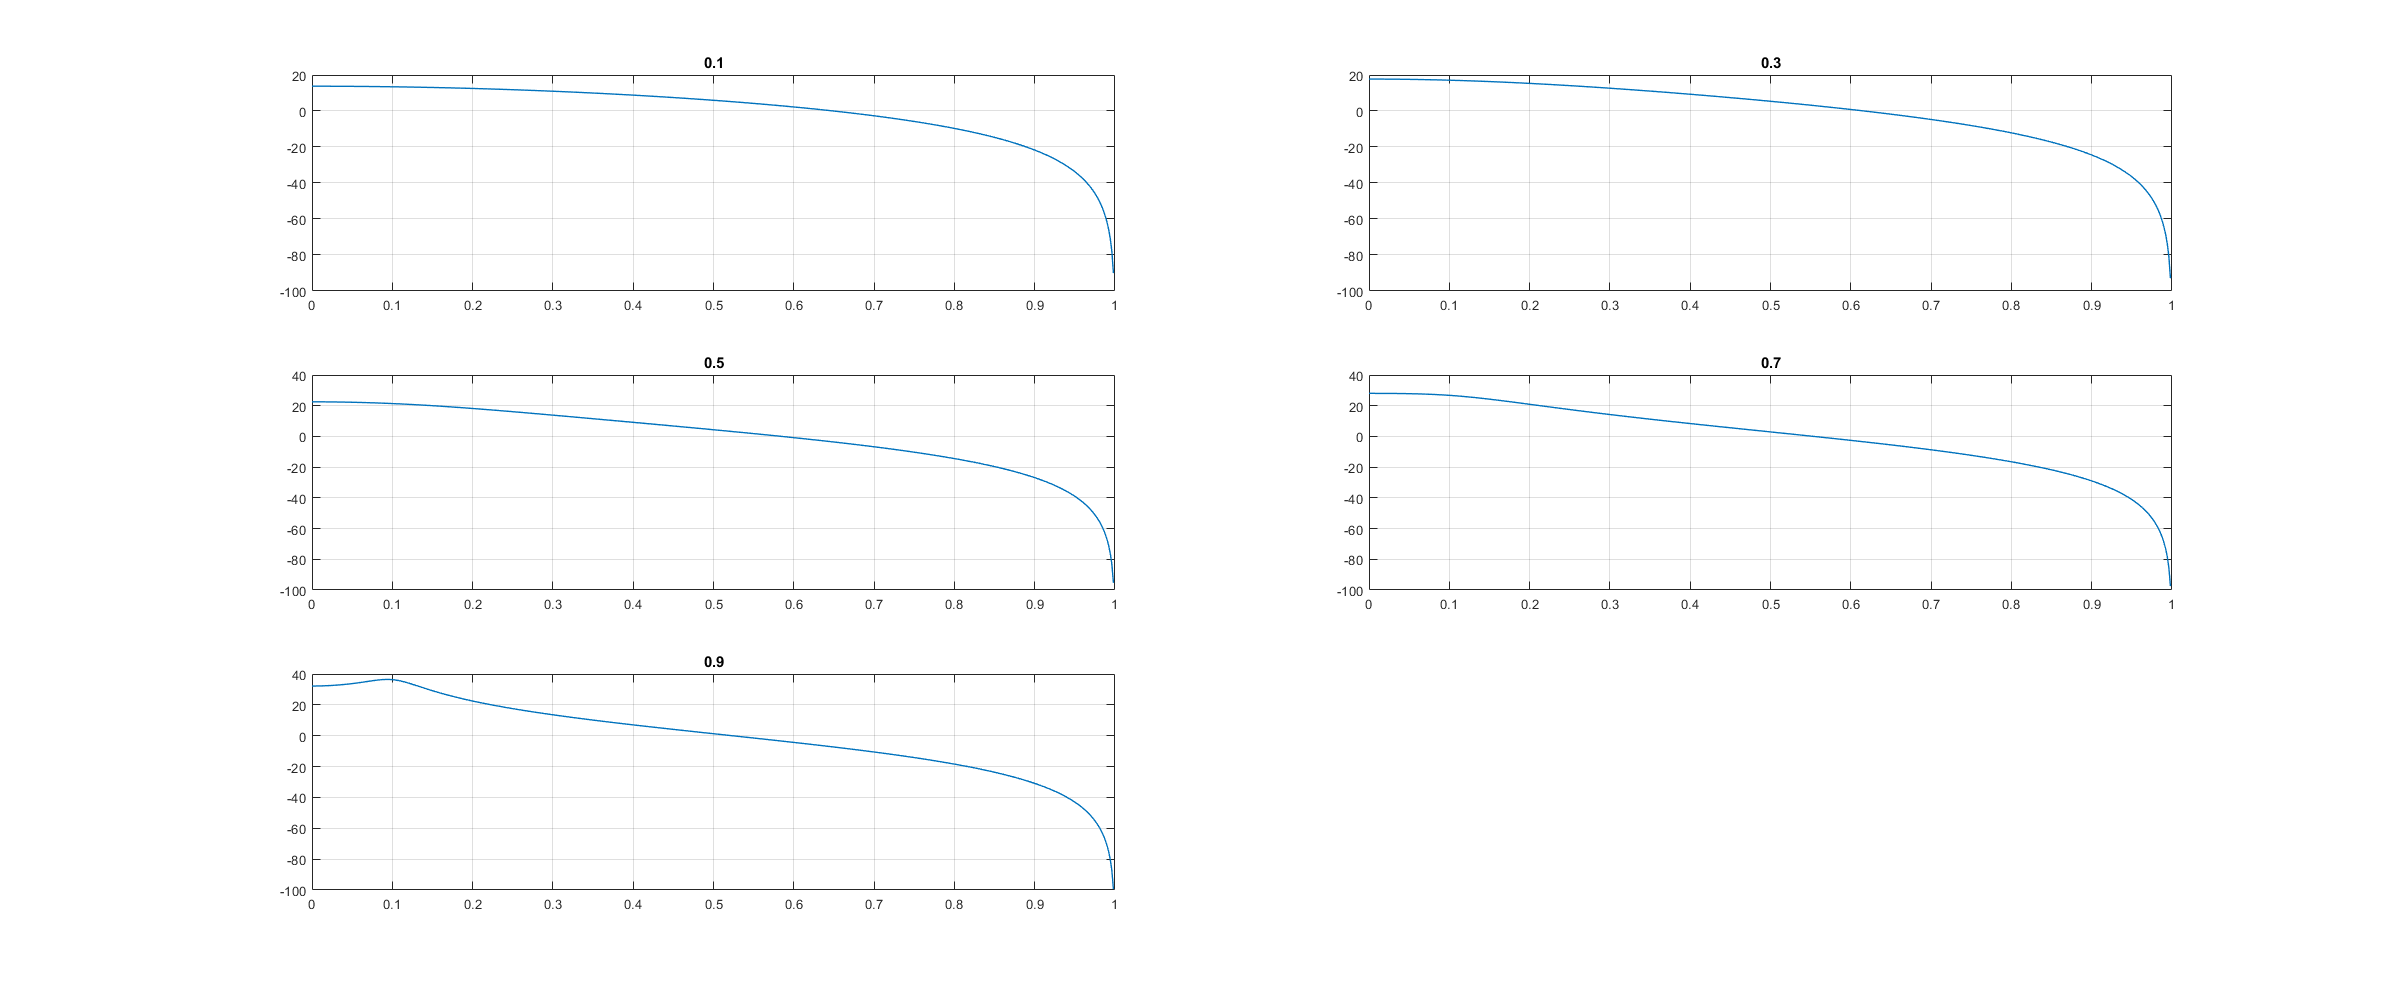

Fs=20000;
f=[1000 2000 3000];
w=2*pi*f/(Fs);
r=0.1; figure('Position',[100 100 2400 1000]);
for i=1:5
     m_1=-2*r*cos(w(1));
    m_2=r^2;
    
    [H1,W]=freqz([1 2 1],[1 m_1 m_2]); 
    subplot(3,2,i);
    plot(W/pi, 20*log10(abs(H1)), 'LineWidth',1 ); grid on;
    title(sprintf('%.1f', r));
    r=r+0.2;
end

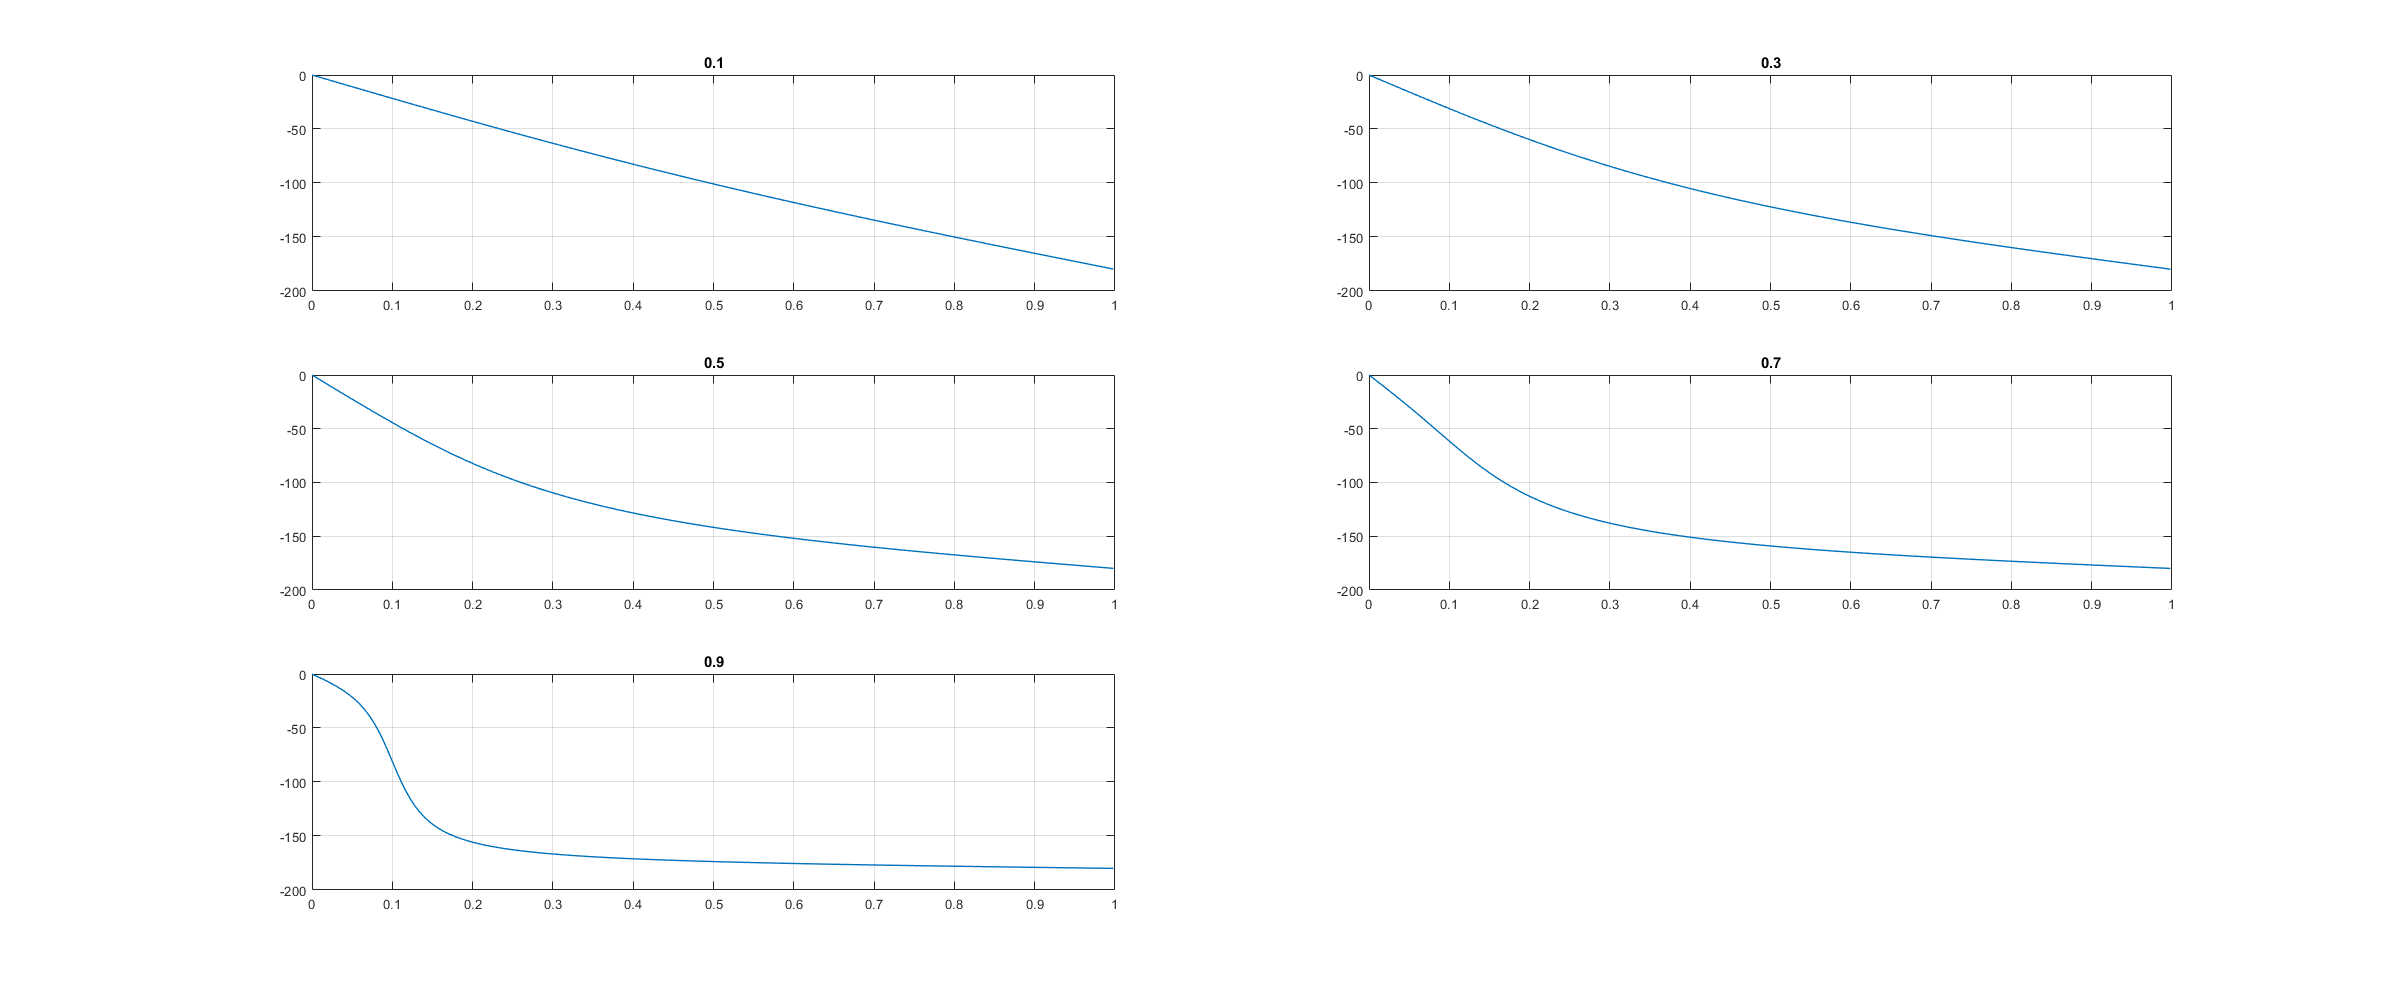


r=0.1; figure('Position',[100 100 2400 1000]);
for i=1:5
     m_1=-2*r*cos(w(1));
    m_2=r^2;
    
    [H1,W]=freqz([1 2 1],[1 m_1 m_2]); 
    subplot(3,2,i);
    plot((W/pi), unwrap(angle(H1))*(180/pi), 'LineWidth',1);grid on;
   

    title(sprintf('%.1f', r));
    r=r+0.2;
end

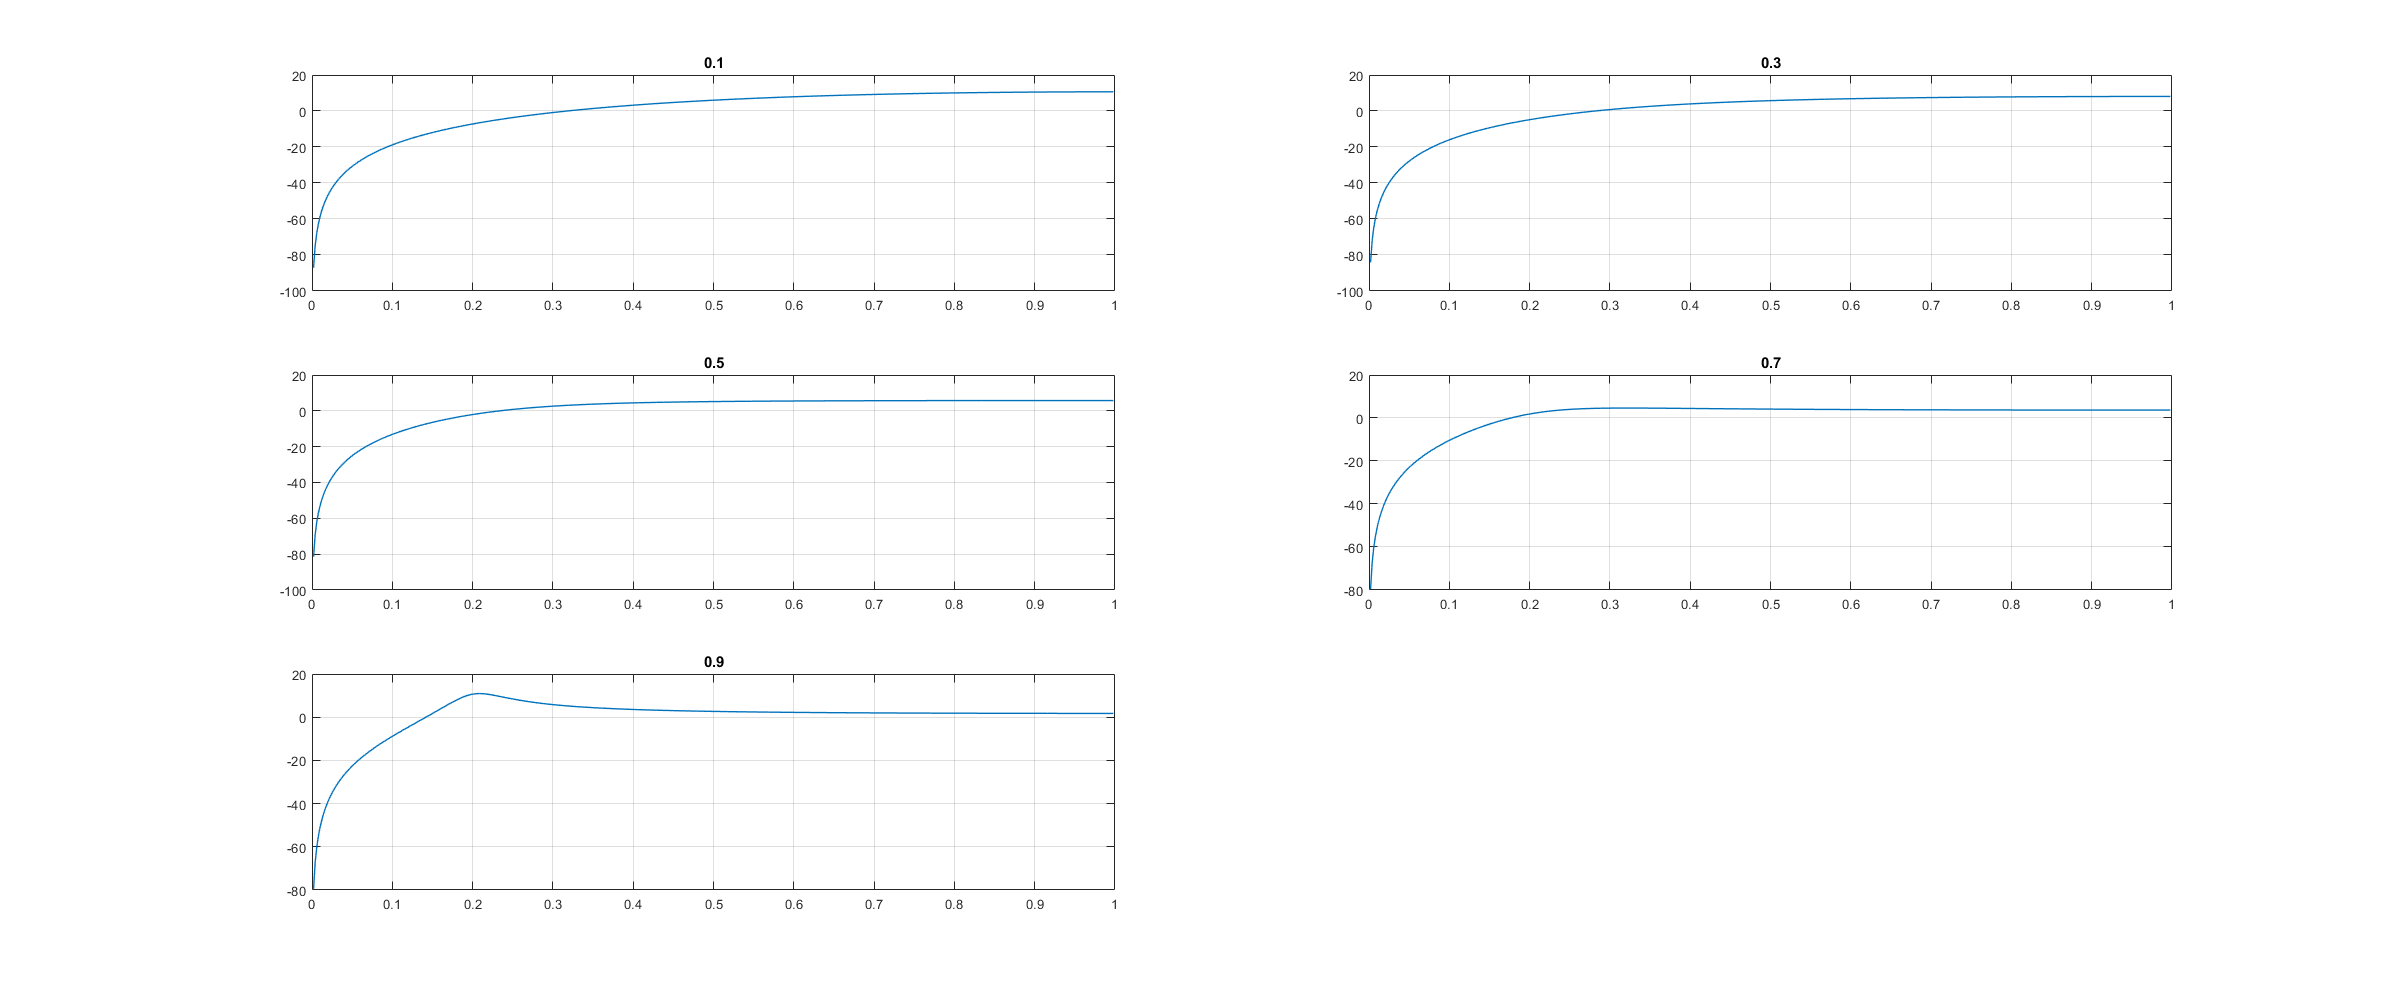



r=0.1; figure('Position',[100 100 2400 1000]);
for i=1:5
    
     m_1=-2*r*cos(w(2));
    m_2=r^2;
    
    
  [H1,W]=freqz([1 -2 1],[1 m_1 m_2]); 
    subplot(3,2,i);
    plot(W/pi, 20*log10(abs(H1)), 'LineWidth',1 ); grid on;
    title(sprintf('%.1f', r));
    r=r+0.2;
end

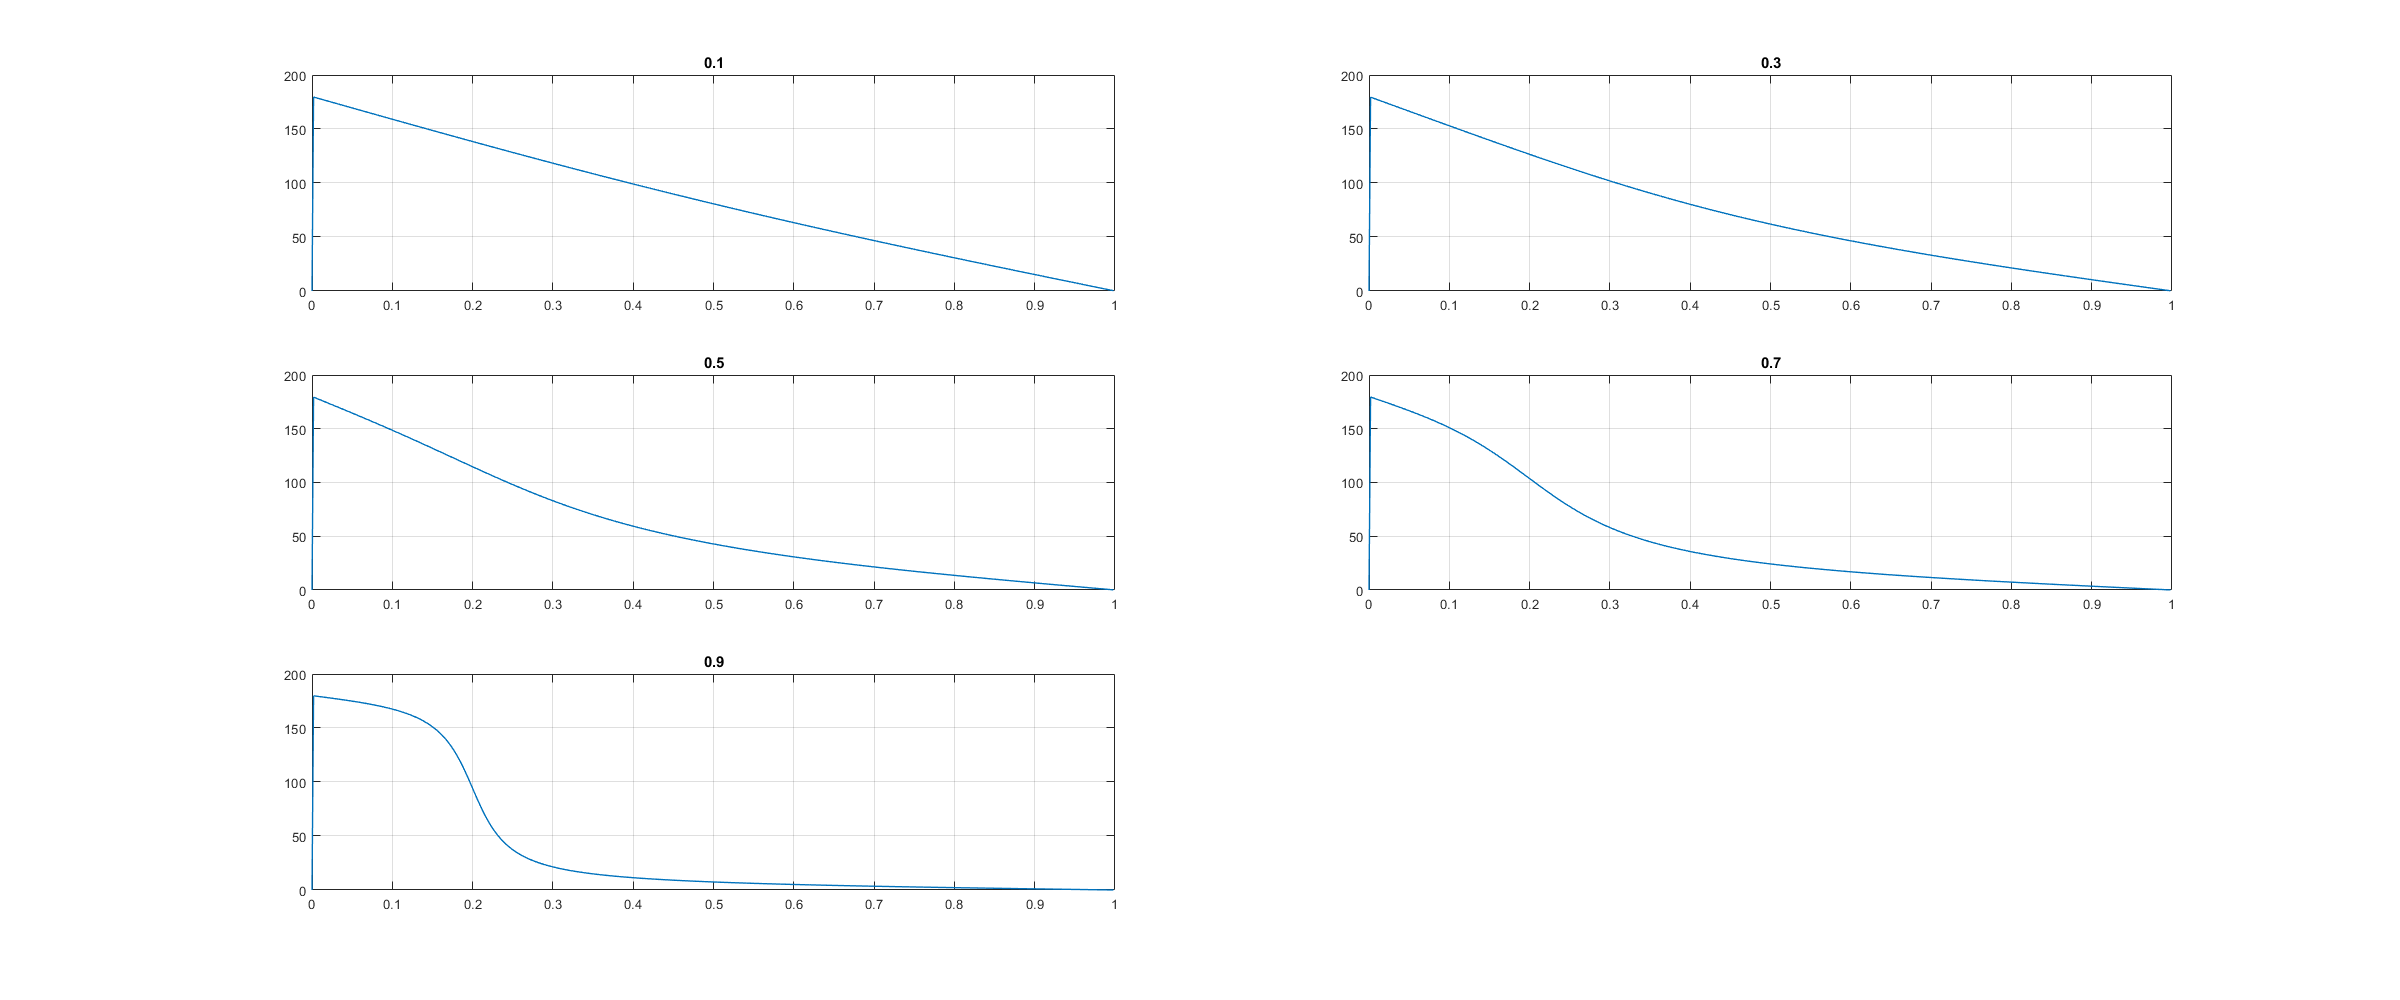

r=0.1; figure('Position',[100 100 2400 1000]);
for i=1:5
    
     m_1=-2*r*cos(w(2));
    m_2=r^2;
    
    
  [H1,W]=freqz([1 -2 1],[1 m_1 m_2]); 
    subplot(3,2,i);
    plot((W/pi), unwrap(angle(H1))*(180/pi), 'LineWidth',1);grid on;
    title(sprintf('%.1f', r));
    r=r+0.2;
end

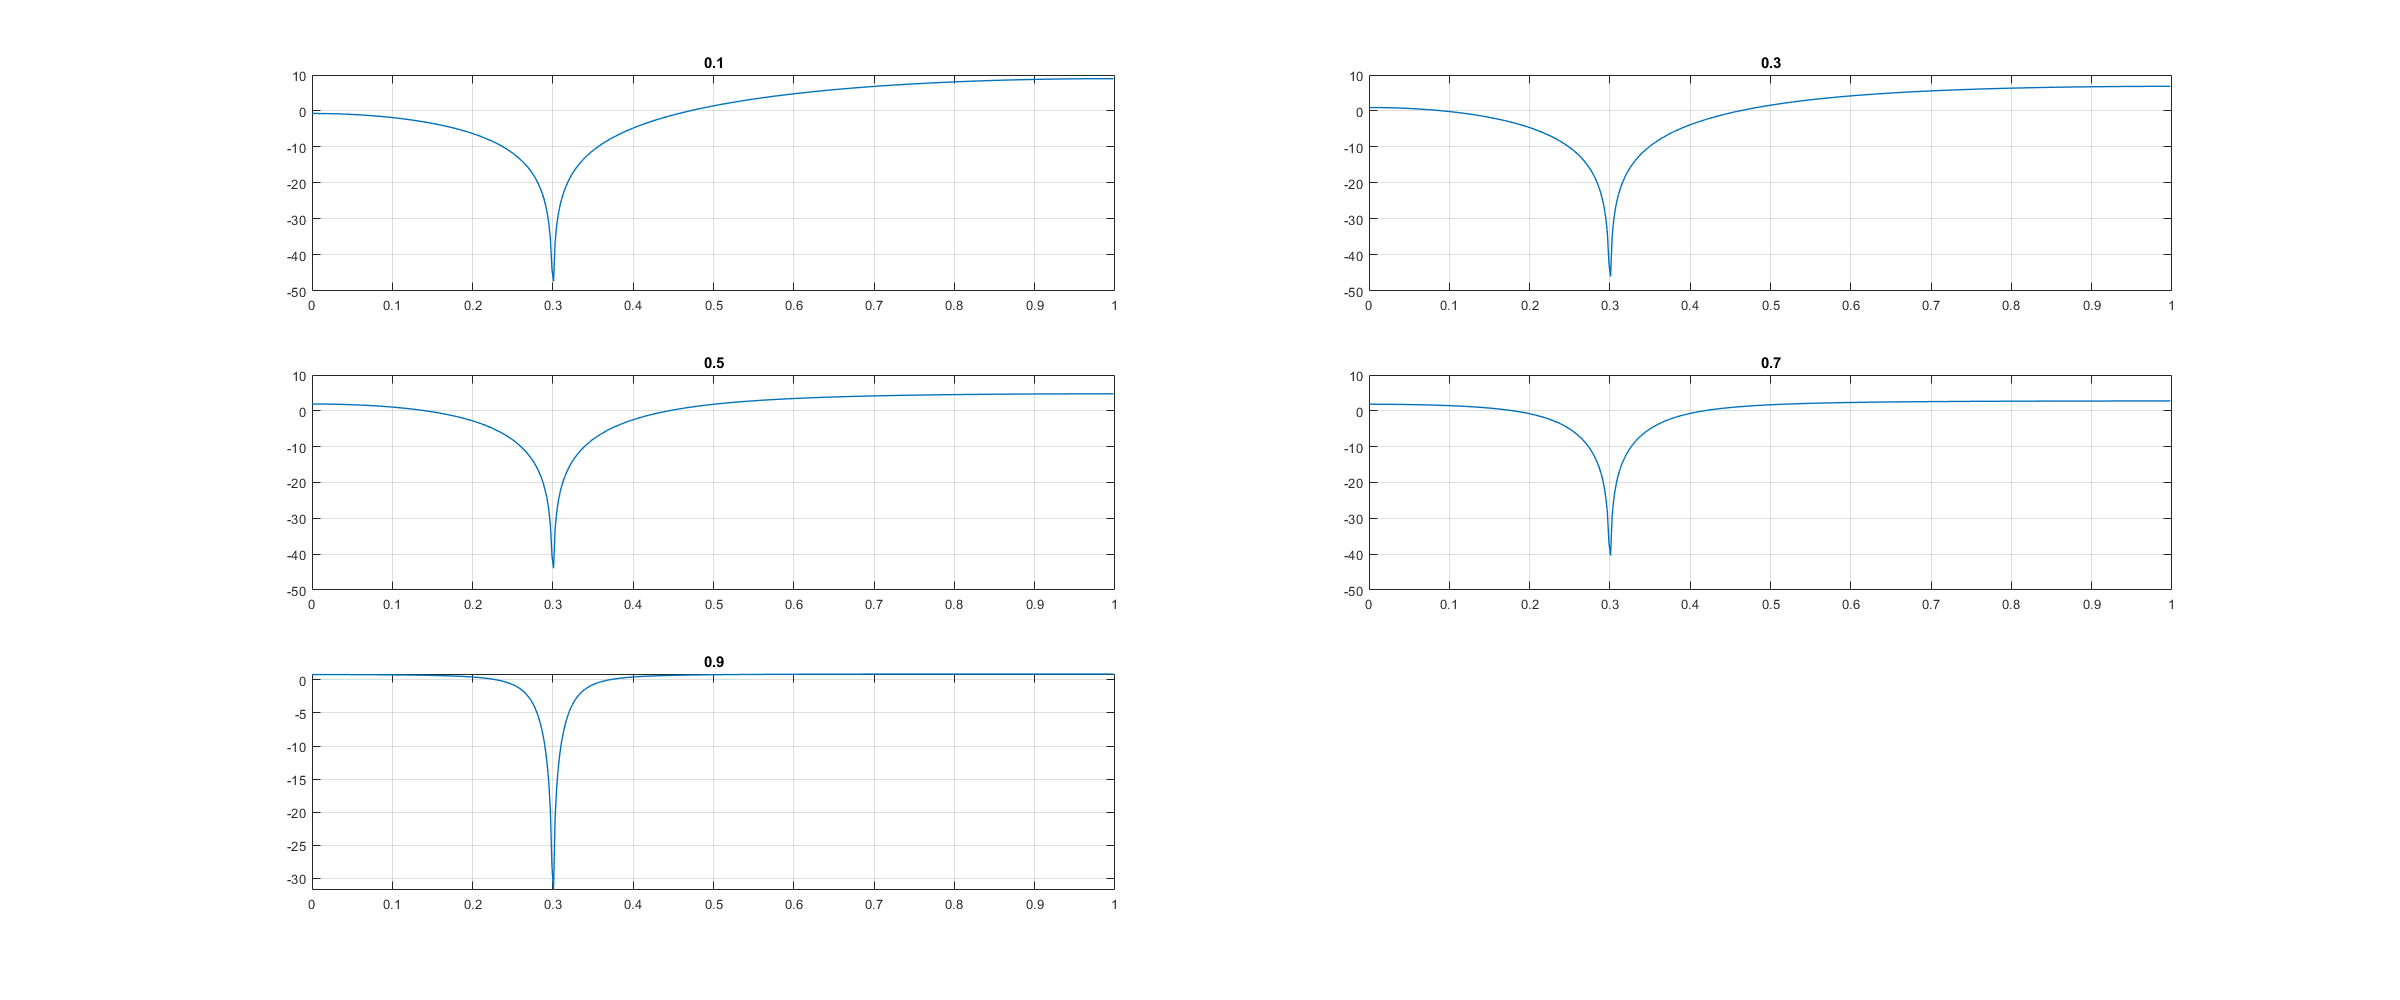

r=0.1; figure('Position',[100 100 2400 1000]);
for i=1:5
    
     m_1=-2*r*cos(w(3));
    m_2=r^2;
    
 [H1,W]=freqz([1 (m_1/sqrt(m_2)) 1],[1 m_1 m_2]);
  subplot(3,2,i);
 plot(W/pi, 20*log10(abs(H1)), 'LineWidth',1 ); grid on;
    title(sprintf('%.1f', r));
    r=r+0.2;
end

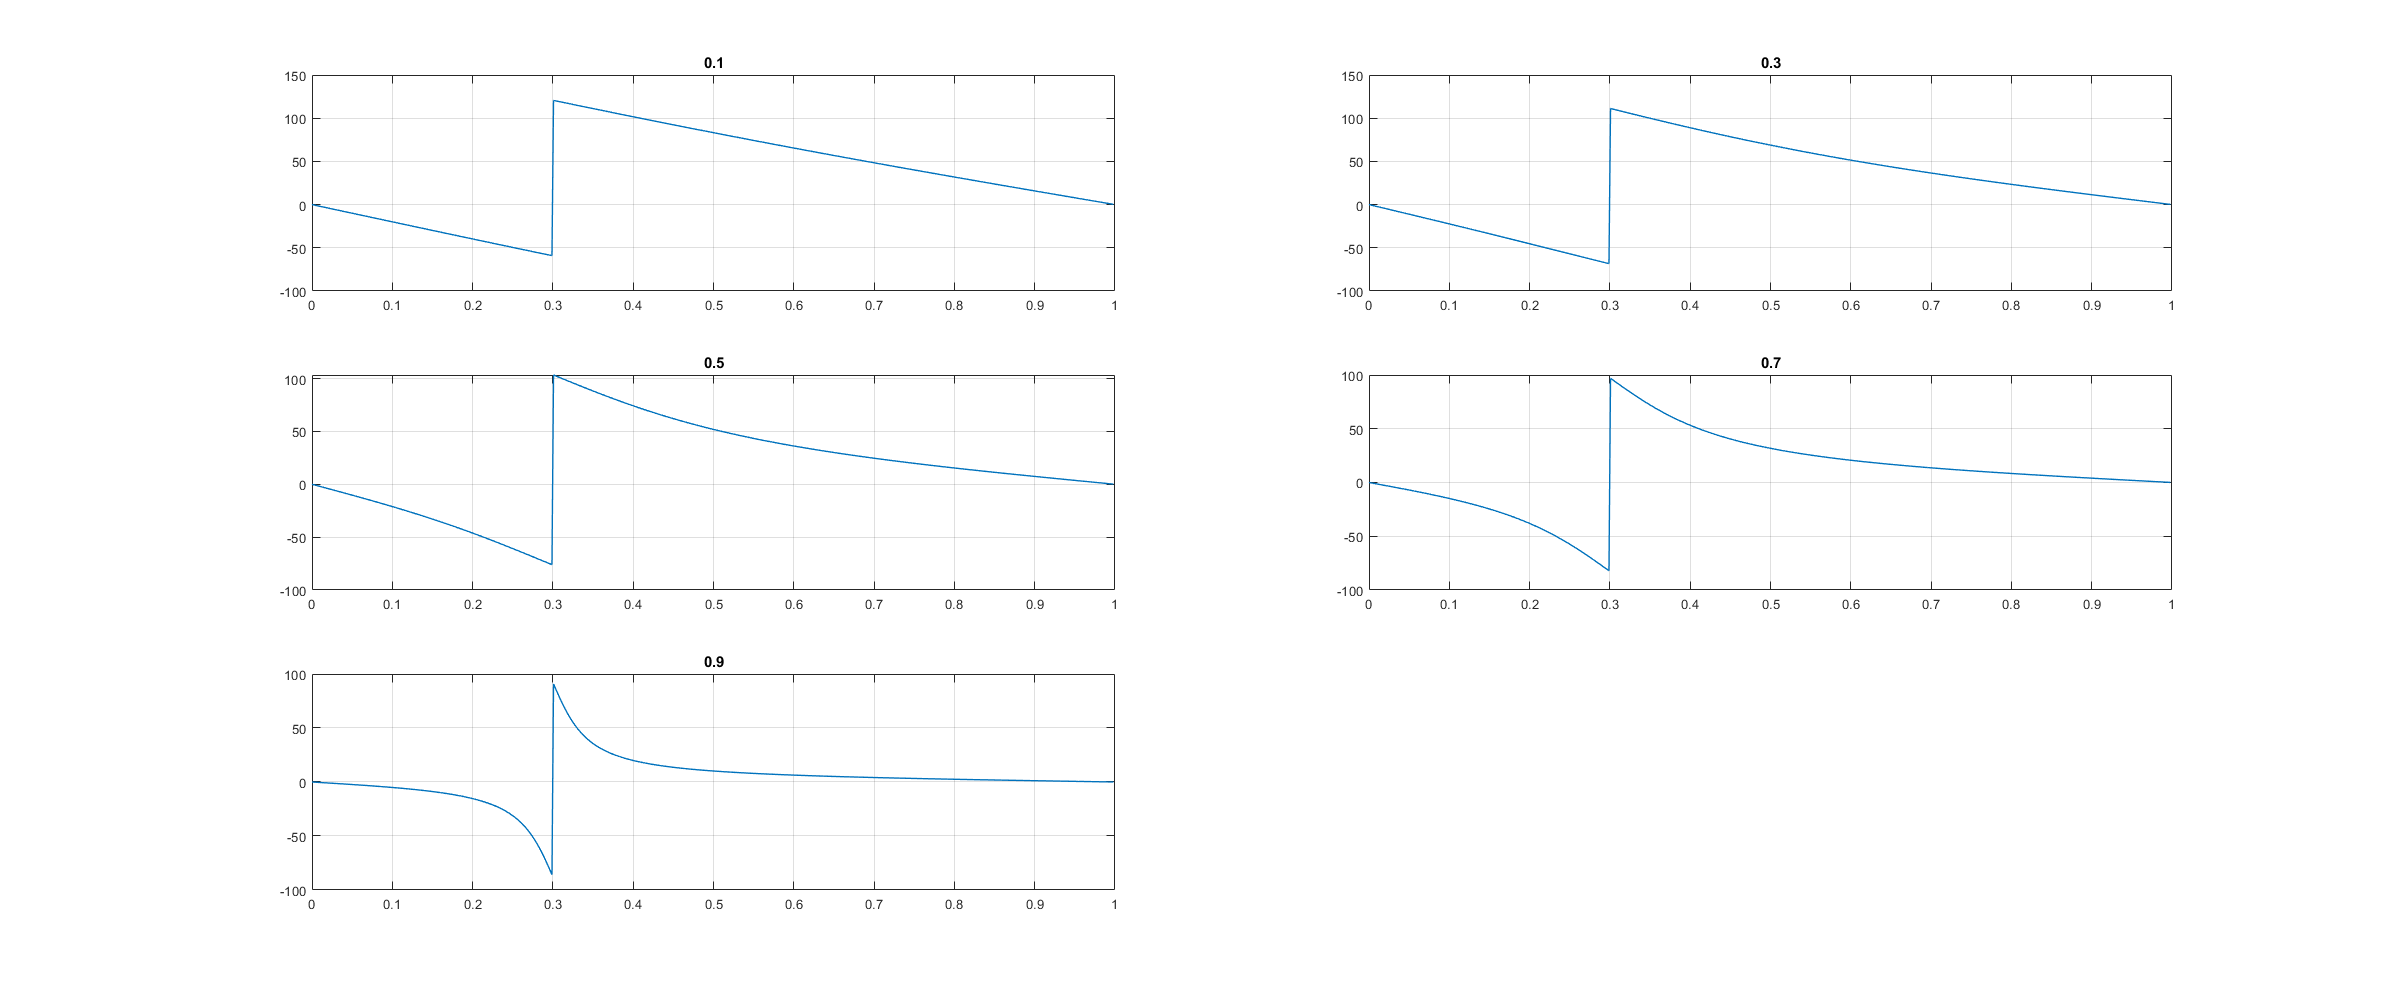

r=0.1; figure('Position',[100 100 2400 1000]);
for i=1:5
    
     m_1=-2*r*cos(w(3));
    m_2=r^2;
    
 [H1,W]=freqz([1 (m_1/sqrt(m_2)) 1],[1 m_1 m_2]);
  subplot(3,2,i);
 plot((W/pi), unwrap(angle(H1))*(180/pi), 'LineWidth',1);grid on;
    title(sprintf('%.1f', r));
    r=r+0.2;
end

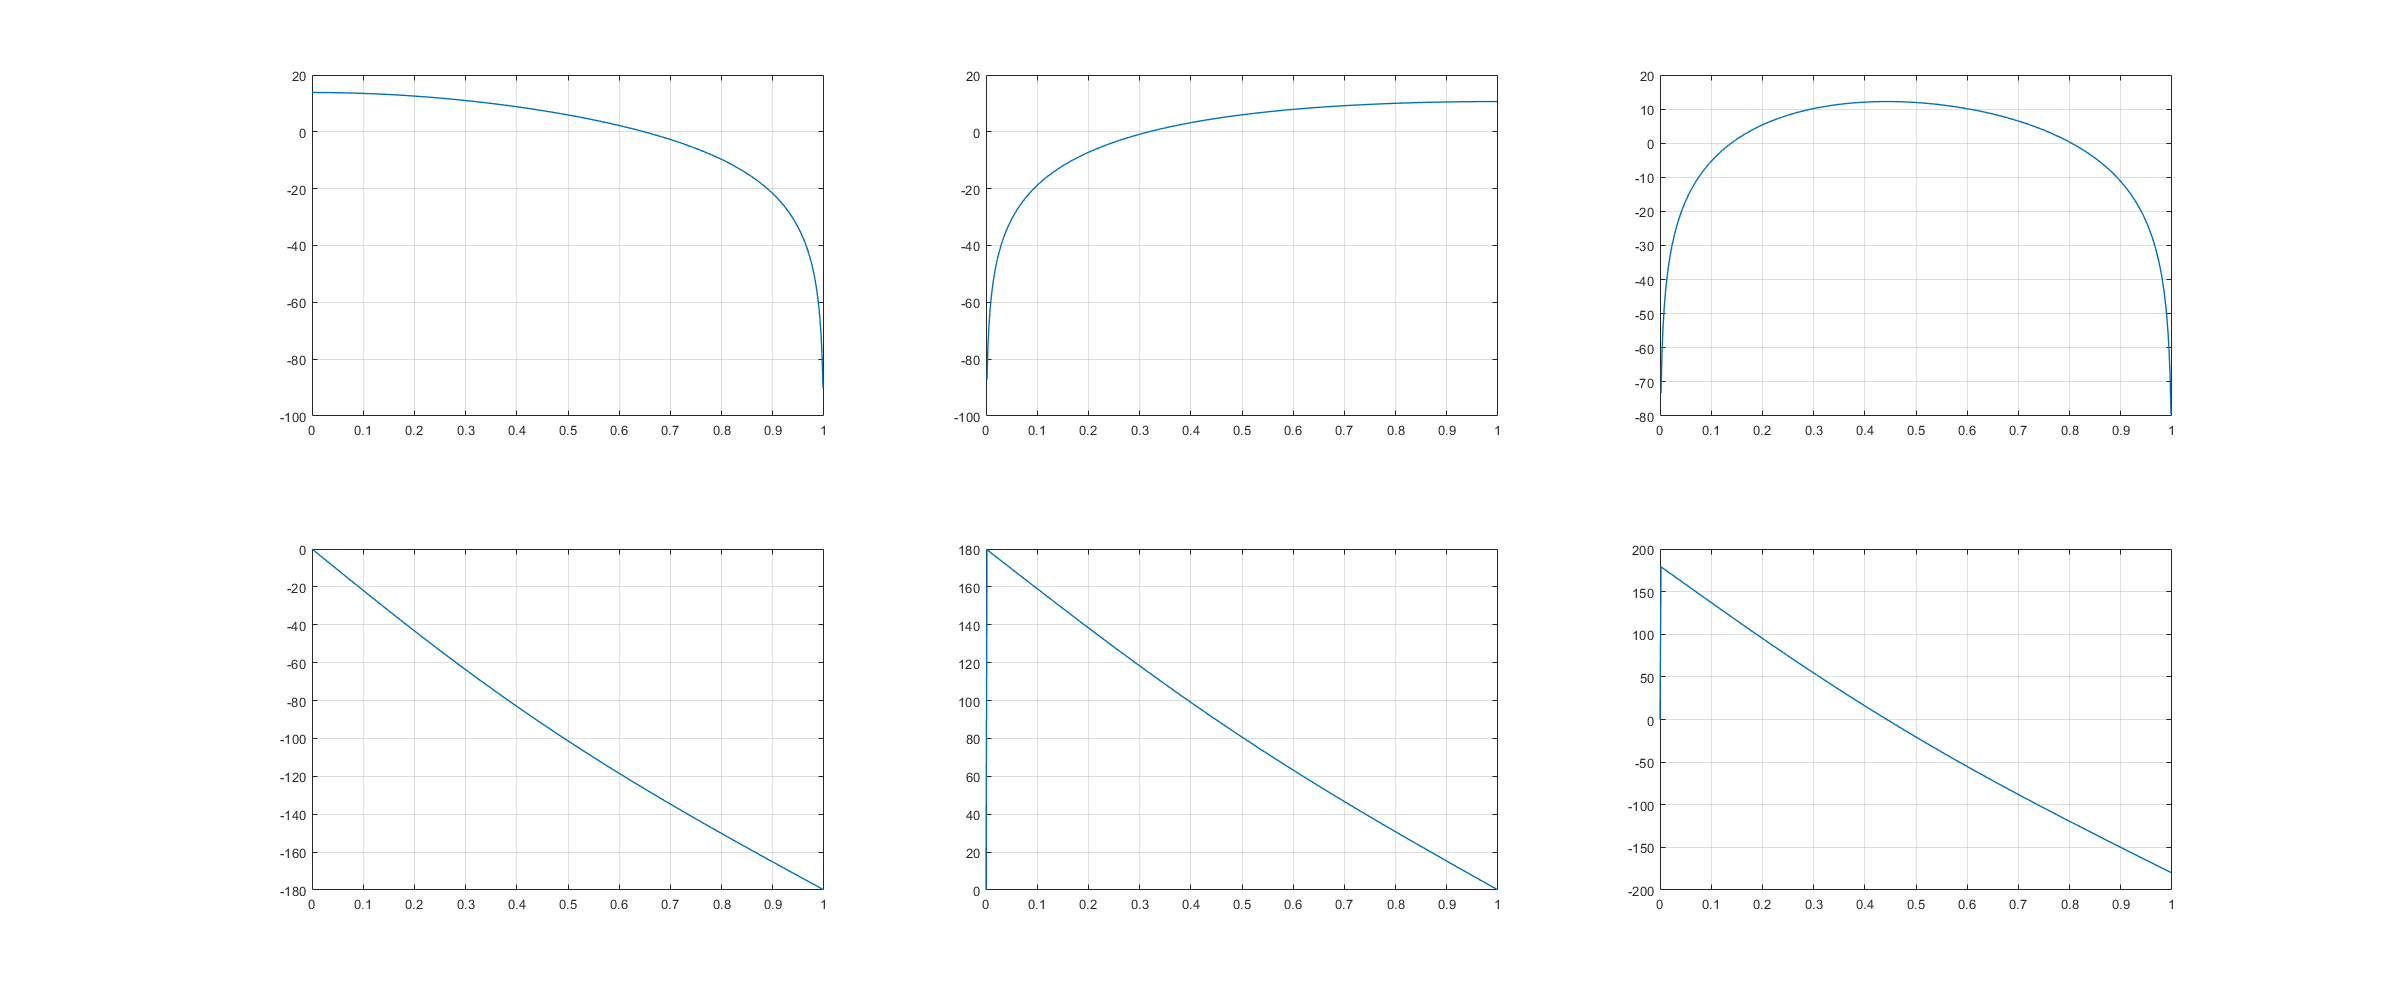

Fs=20000;
f=[500 2000];
w=2*pi*f/(Fs);
r=[0.1 0.1];
%i=1:3
     m_11=-2*r(1)*cos(w);
    m_21=r(1)^2;
    m_12=-2*r(2)*cos(w);
    m_22=r(2)^2;
    Num1=[1 2 1];
    Num2=[1 -2 1];
    Den1=[1 m_11(1) m_21];
    Den2=[1 m_12(2) m_22];
    [H1,W]=freqz(Num1,Den1);
  figure('Position',[100 100 2400 1000]);  
  subplot(2,3,1);
 plot(W/pi, 20*log10(abs(H1)), 'LineWidth',1 ); grid on;
 subplot(2,3,4);
 plot((W/pi), unwrap(angle(H1))*(180/pi), 'LineWidth',1);grid on;
 
    [H1,W]=freqz(Num2,Den2);
    subplot(2,3,2);
 plot(W/pi, 20*log10(abs(H1)), 'LineWidth',1 ); grid on;
 subplot(2,3,5);
 plot((W/pi), unwrap(angle(H1))*(180/pi), 'LineWidth',1);grid on;
   
    [H1,W]=freqz(conv(Num1,Num2),conv(Den1,Den2)); 
    subplot(2,3,3);
 plot(W/pi, 20*log10(abs(H1)), 'LineWidth',1 ); grid on;
 subplot(2,3,6);
 plot((W/pi), unwrap(angle(H1))*(180/pi), 'LineWidth',1);grid on;

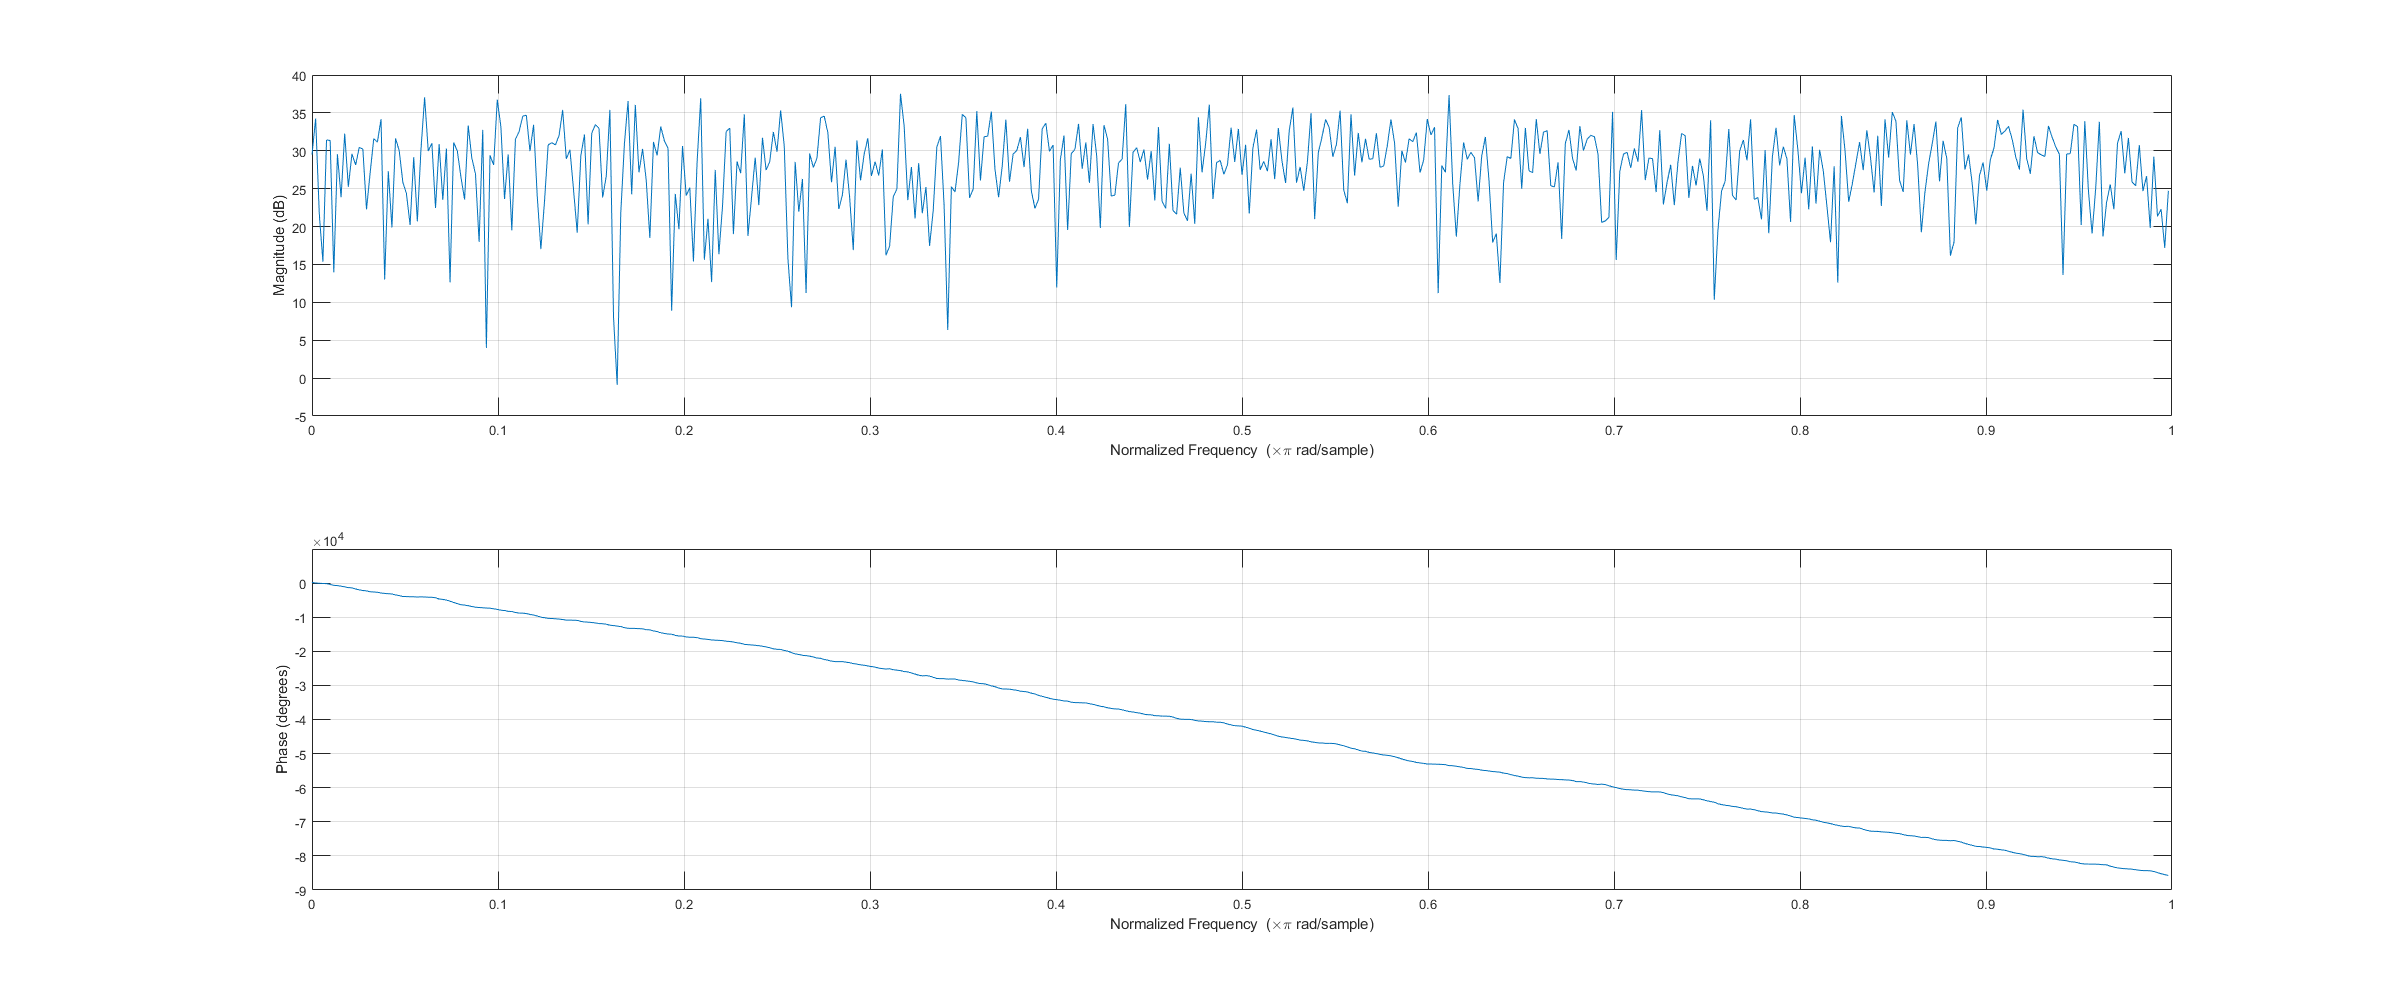

    
%end
noise=randn(1,1000);
figure('Position',[100 100 2400 1000]);  
subplot(1,2,1);
freqz(noise);

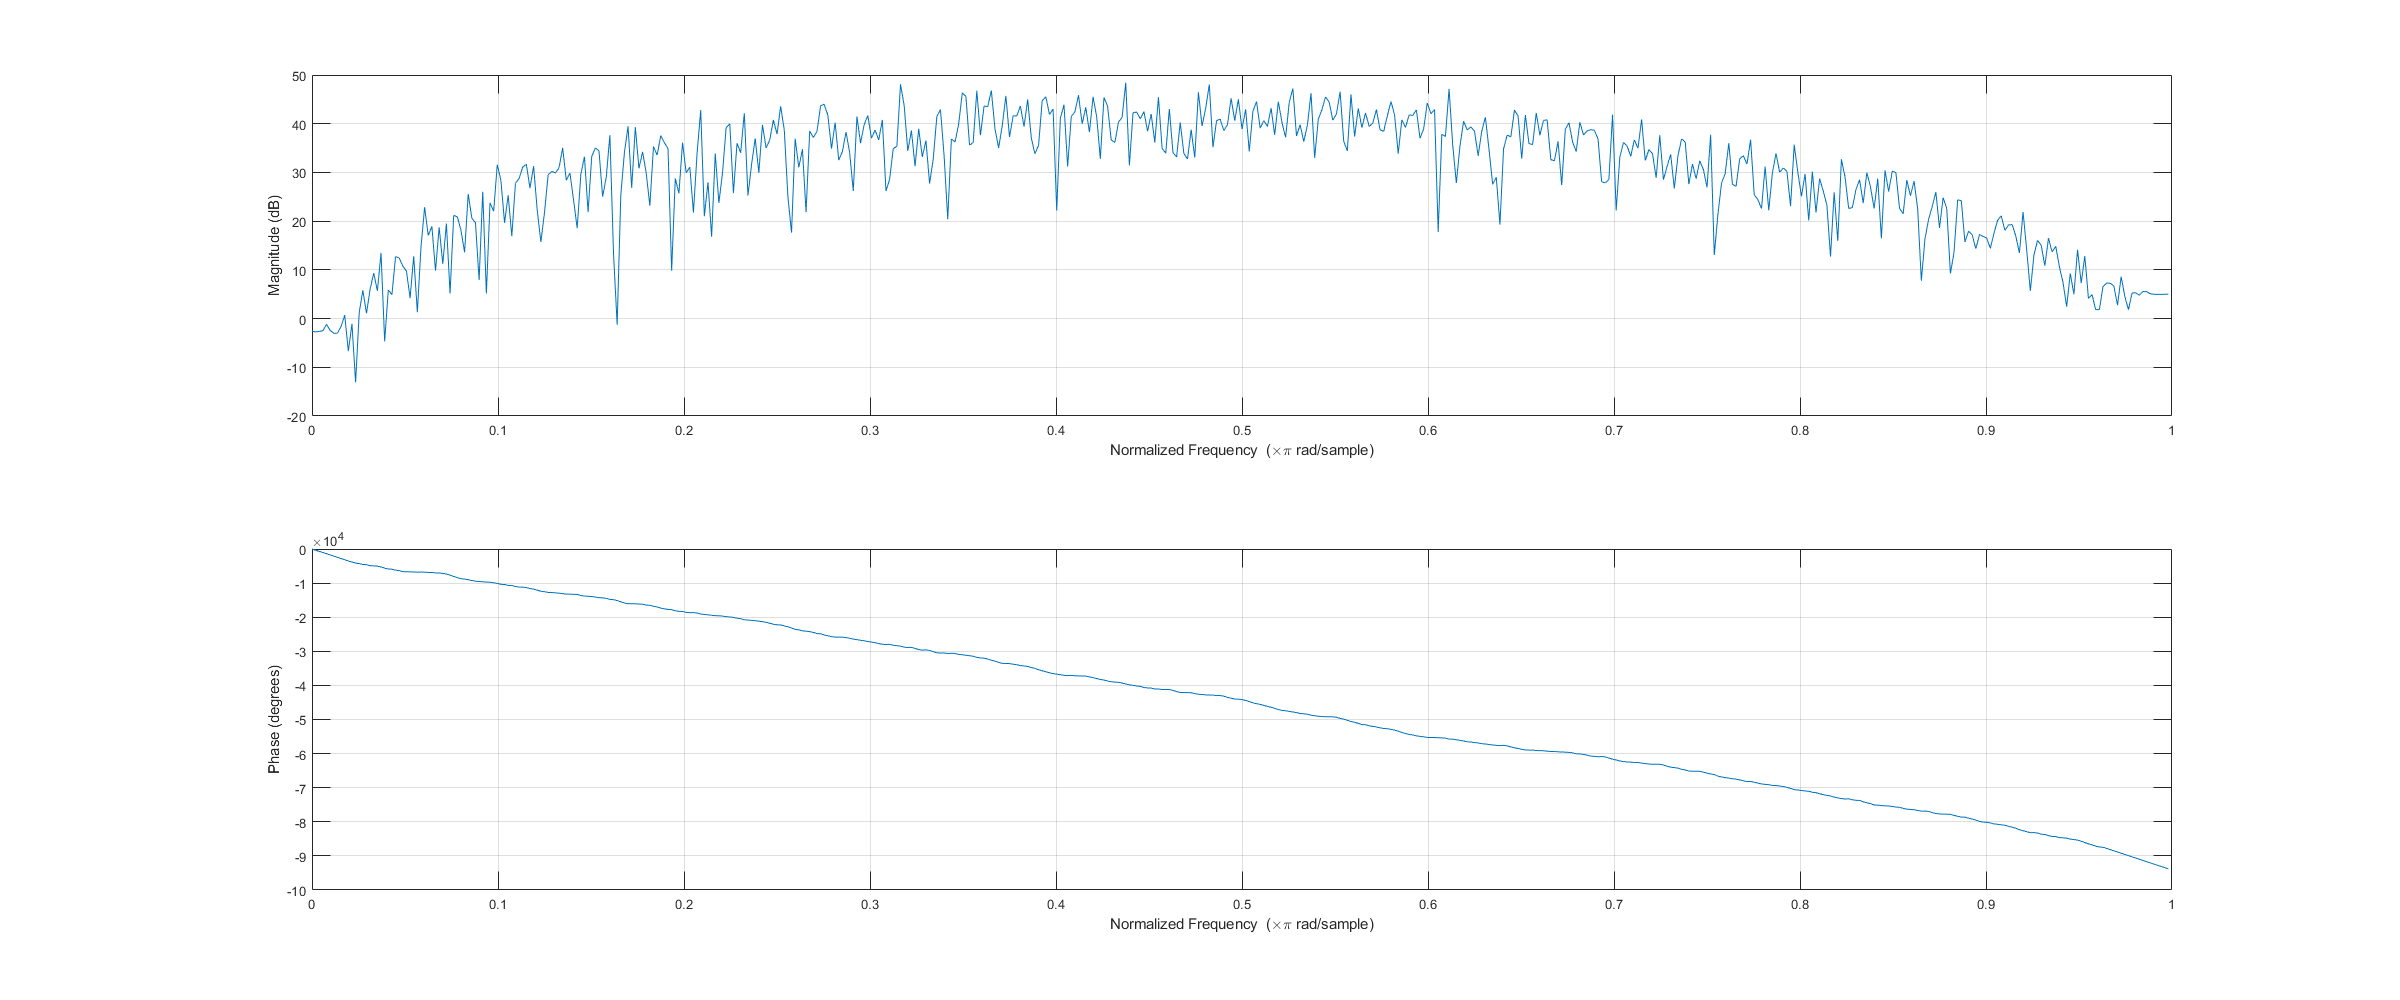




 subplot(1,2,2);
yu=filter(conv(Num1,Num2),conv(Den1,Den2),noise);
freqz(yu);

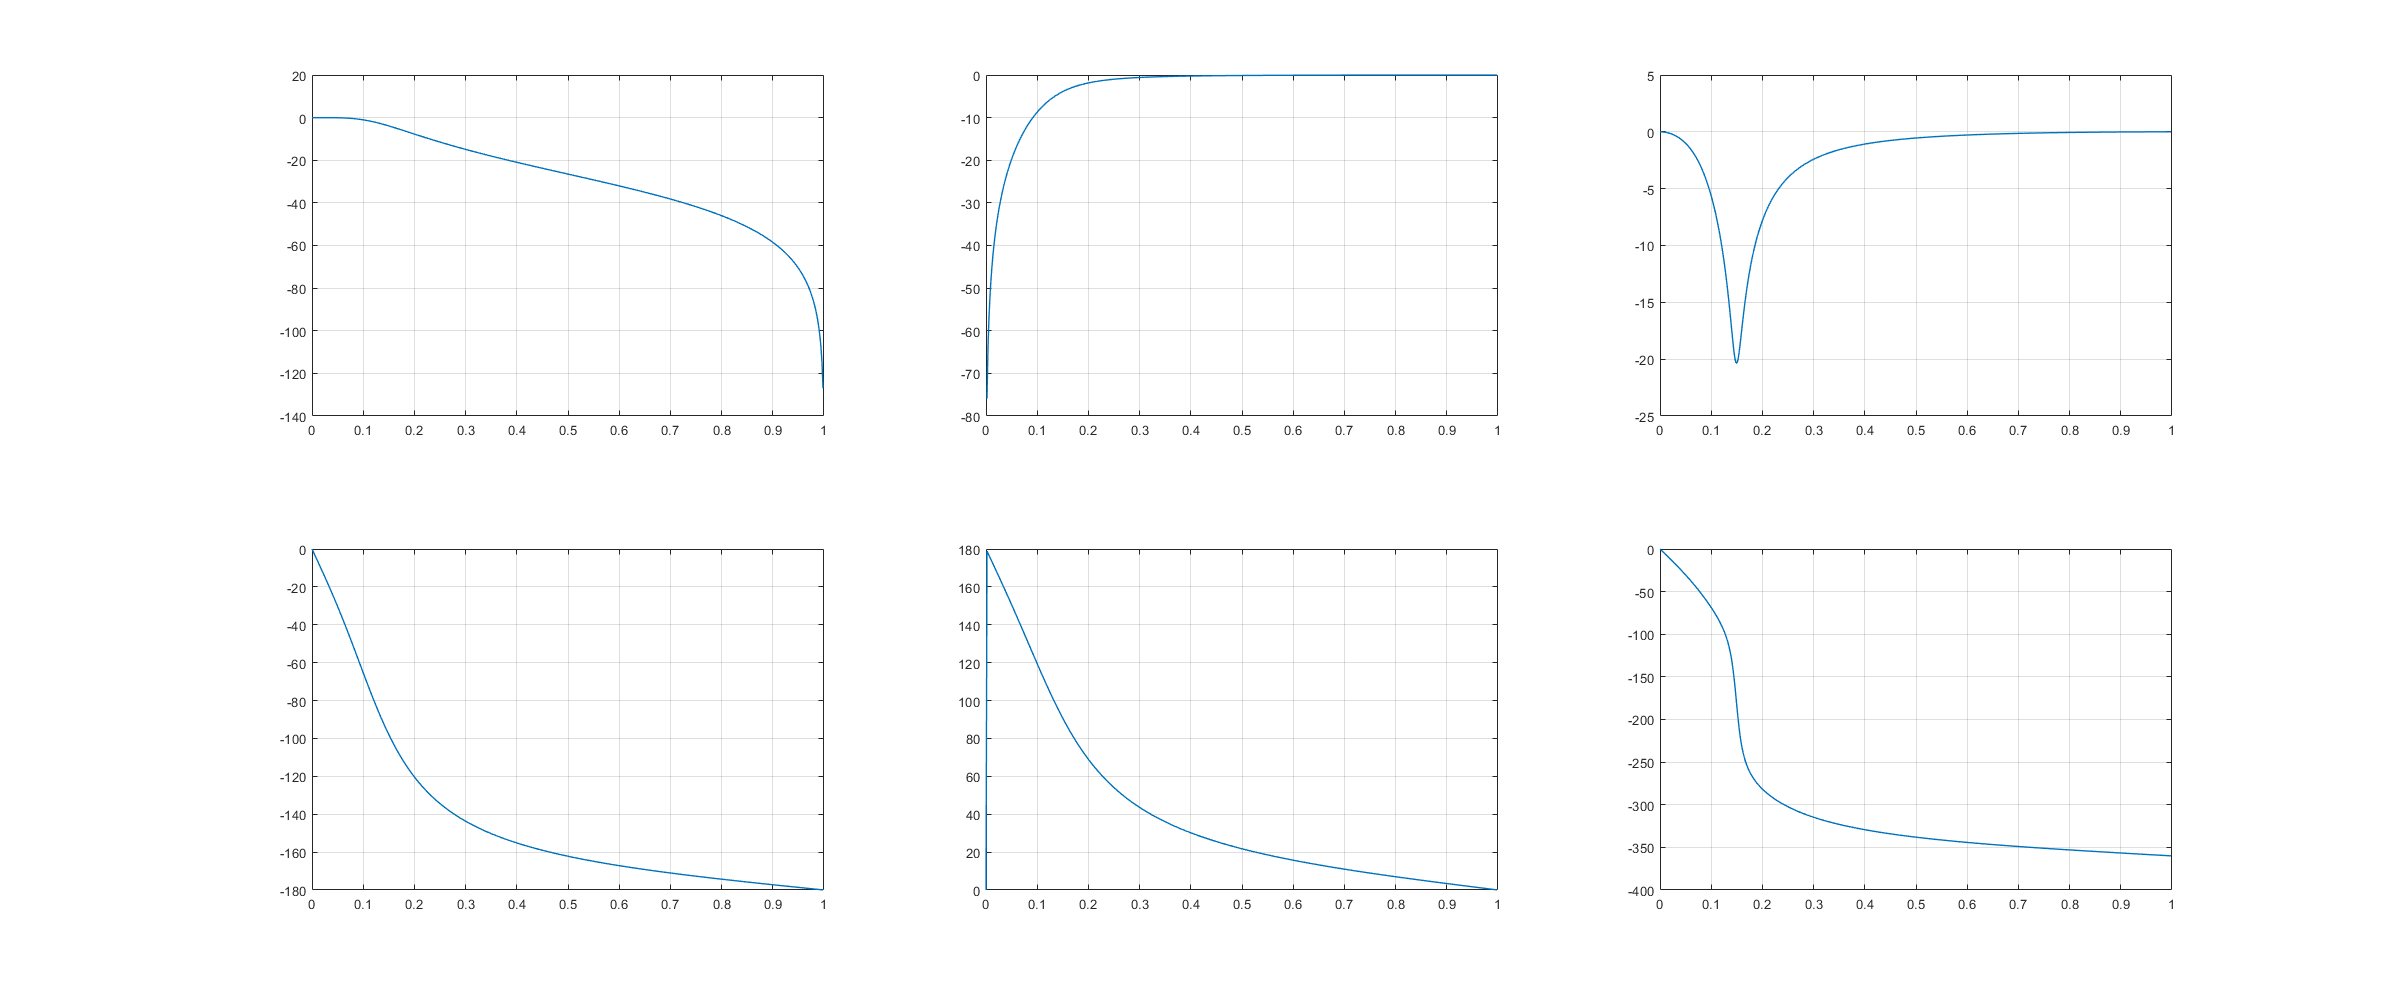

Fs=20000;
f=[1000 2500];
w=2*pi*f/(Fs);
r1=0.74;
r2=0.69;

%i=1:3
     m_11=-2*r1*cos(w);
    m_21=r1^2;
    m_12=-2*r2*cos(w);
    m_22=r2^2;
   
    figure;
    
    K1=(abs(4/(1+m_11(1)+m_21)))^-1;
    K2=(abs(4/(1+m_22-m_12(1))))^-1;
    Num1=K1*[1 2 1];
    Num2=K2*[1 -2 1];
    Den1=[1 m_11(1) m_21];
    Den2=[1 m_12(1) m_22];
        [H1,W]=freqz(Num1,Den1);
  figure('Position',[100 100 2400 1000]);  
  subplot(2,3,1);
 plot(W/pi, 20*log10(abs(H1)), 'LineWidth',1 ); grid on;
 subplot(2,3,4);
 plot((W/pi), unwrap(angle(H1))*(180/pi), 'LineWidth',1);grid on;
 
    [H1,W]=freqz(Num2,Den2);
    subplot(2,3,2);
 plot(W/pi, 20*log10(abs(H1)), 'LineWidth',1 ); grid on;
 subplot(2,3,5);
 plot((W/pi), unwrap(angle(H1))*(180/pi), 'LineWidth',1);grid on;
   
    [H1,W]=freqz(conv(Num1,Den2)+conv(Num2,Den1),conv(Den1,Den2));
    subplot(2,3,3);
 plot(W/pi, 20*log10(abs(H1)), 'LineWidth',1 ); grid on;
 subplot(2,3,6);
 plot((W/pi), unwrap(angle(H1))*(180/pi), 'LineWidth',1);grid on;

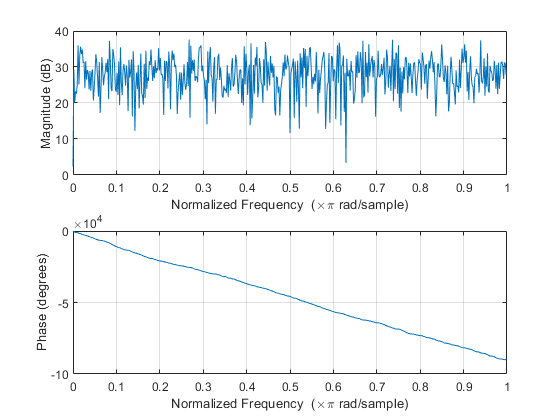

    
    
   
    

noise=randn(1,1000);
figure;
freqz(noise);

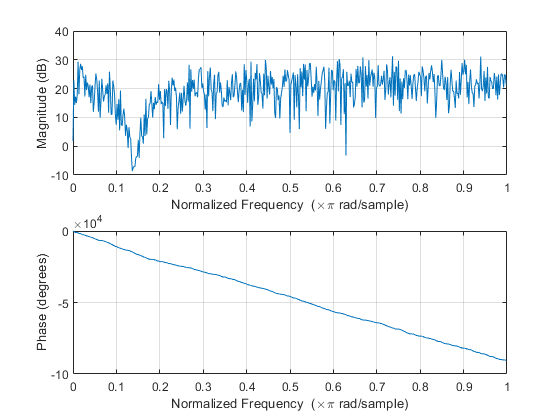

figure;
yu=filter(Num1+Num2,Den1+Den2,noise);
freqz(yu);

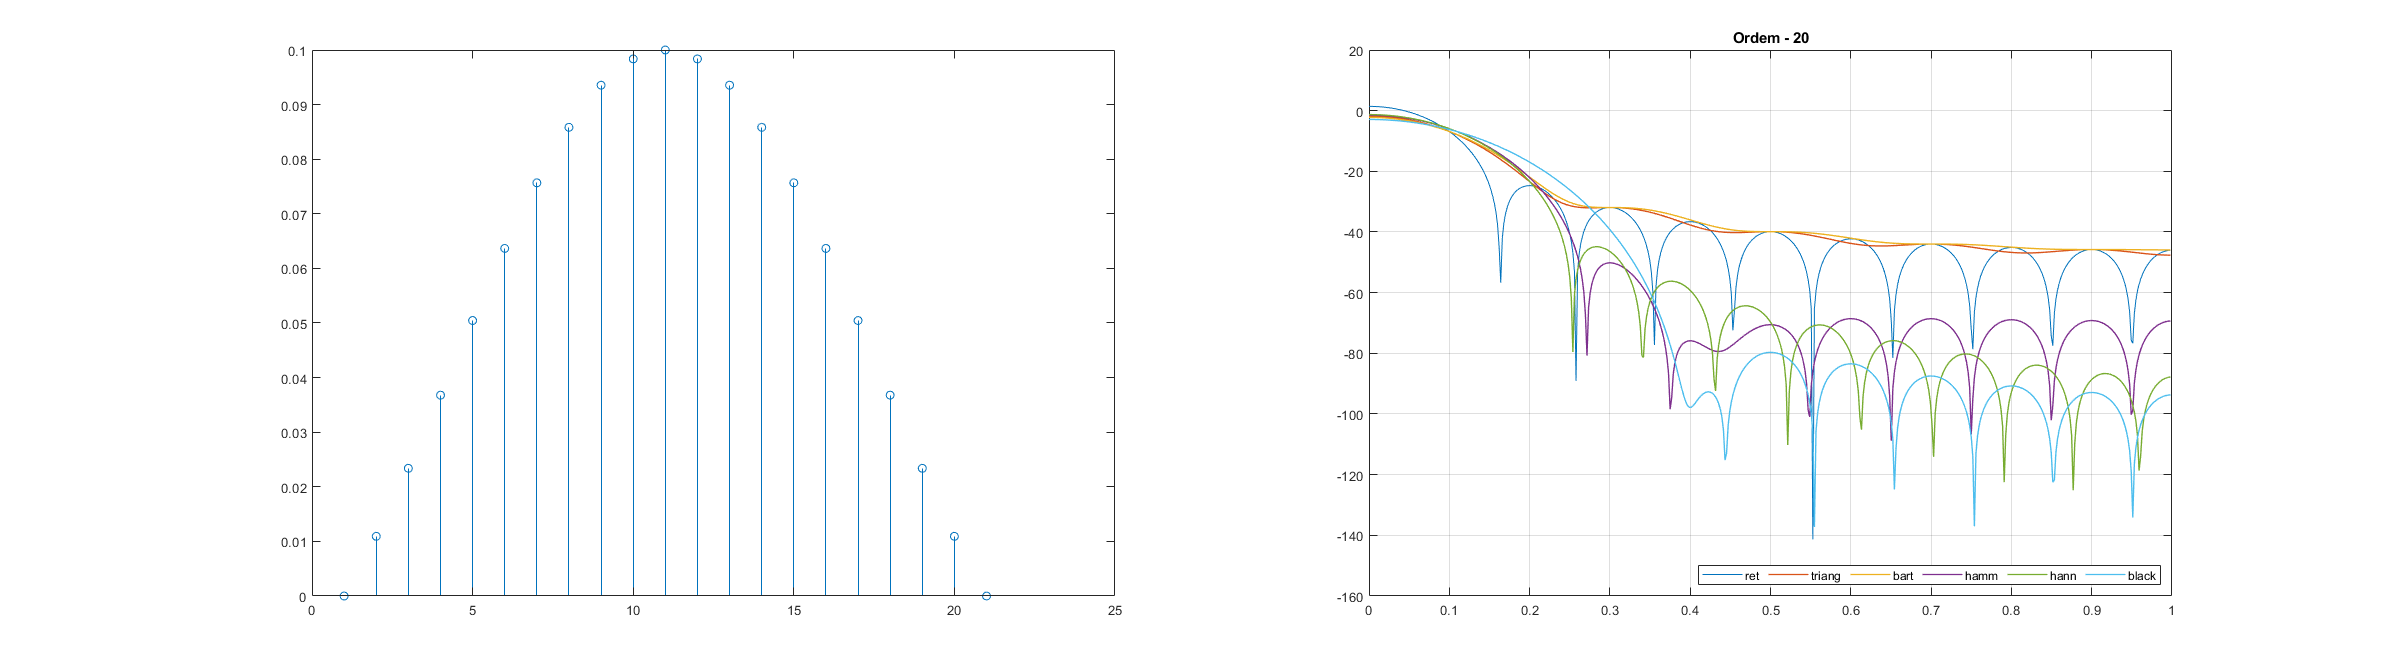

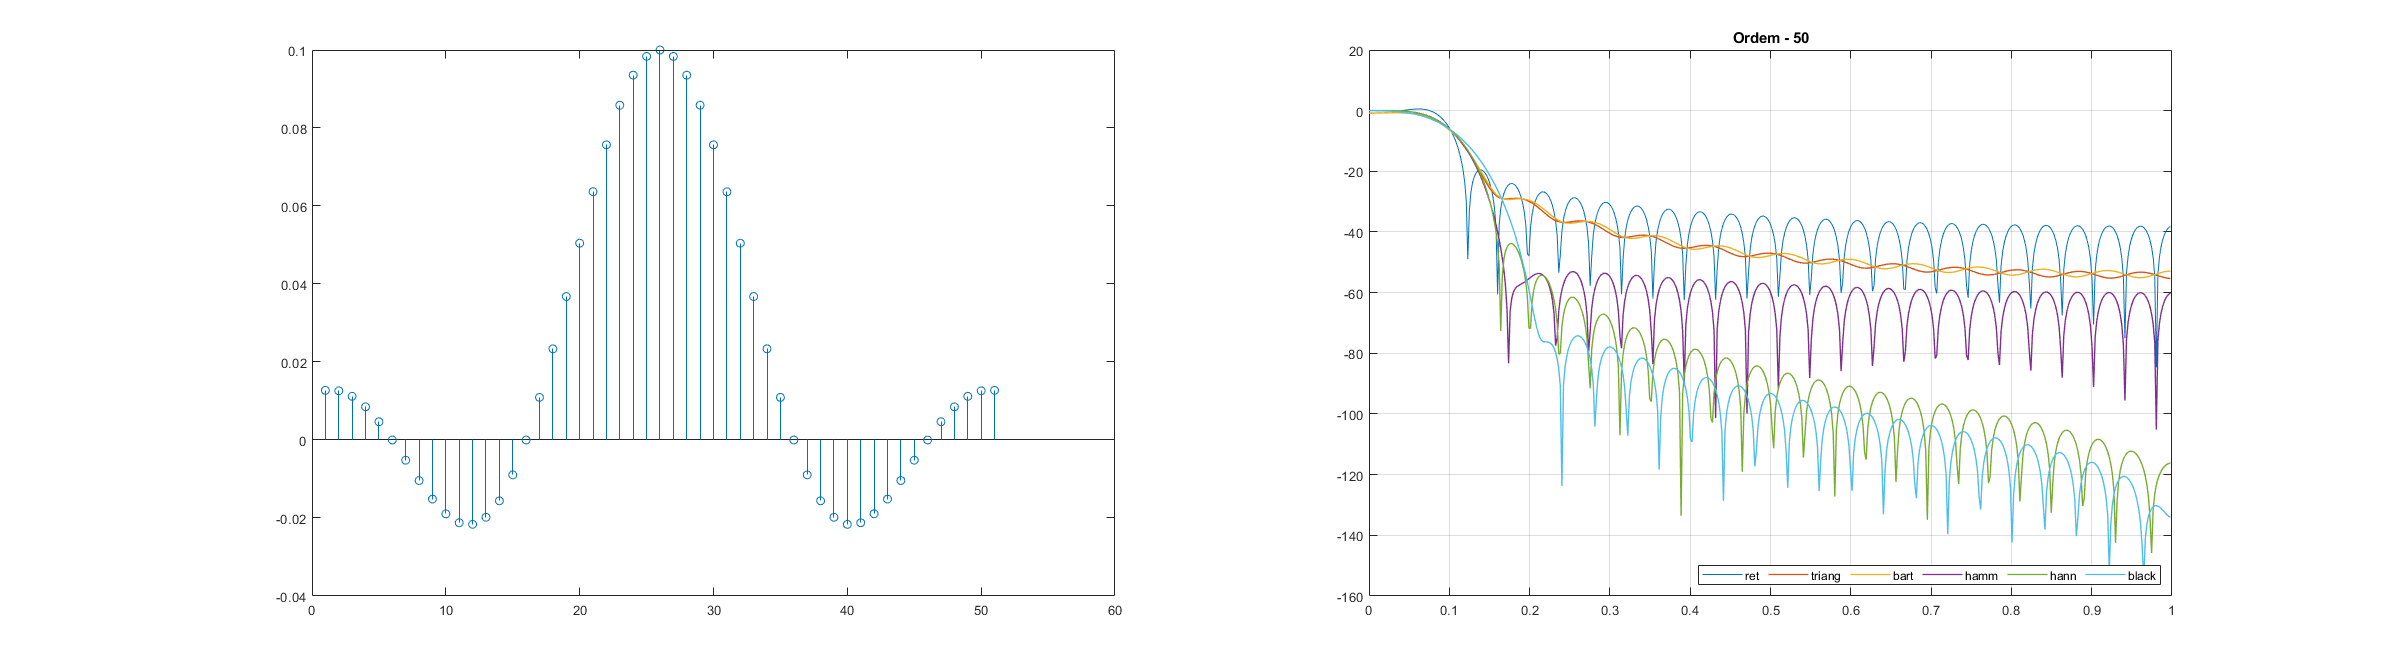

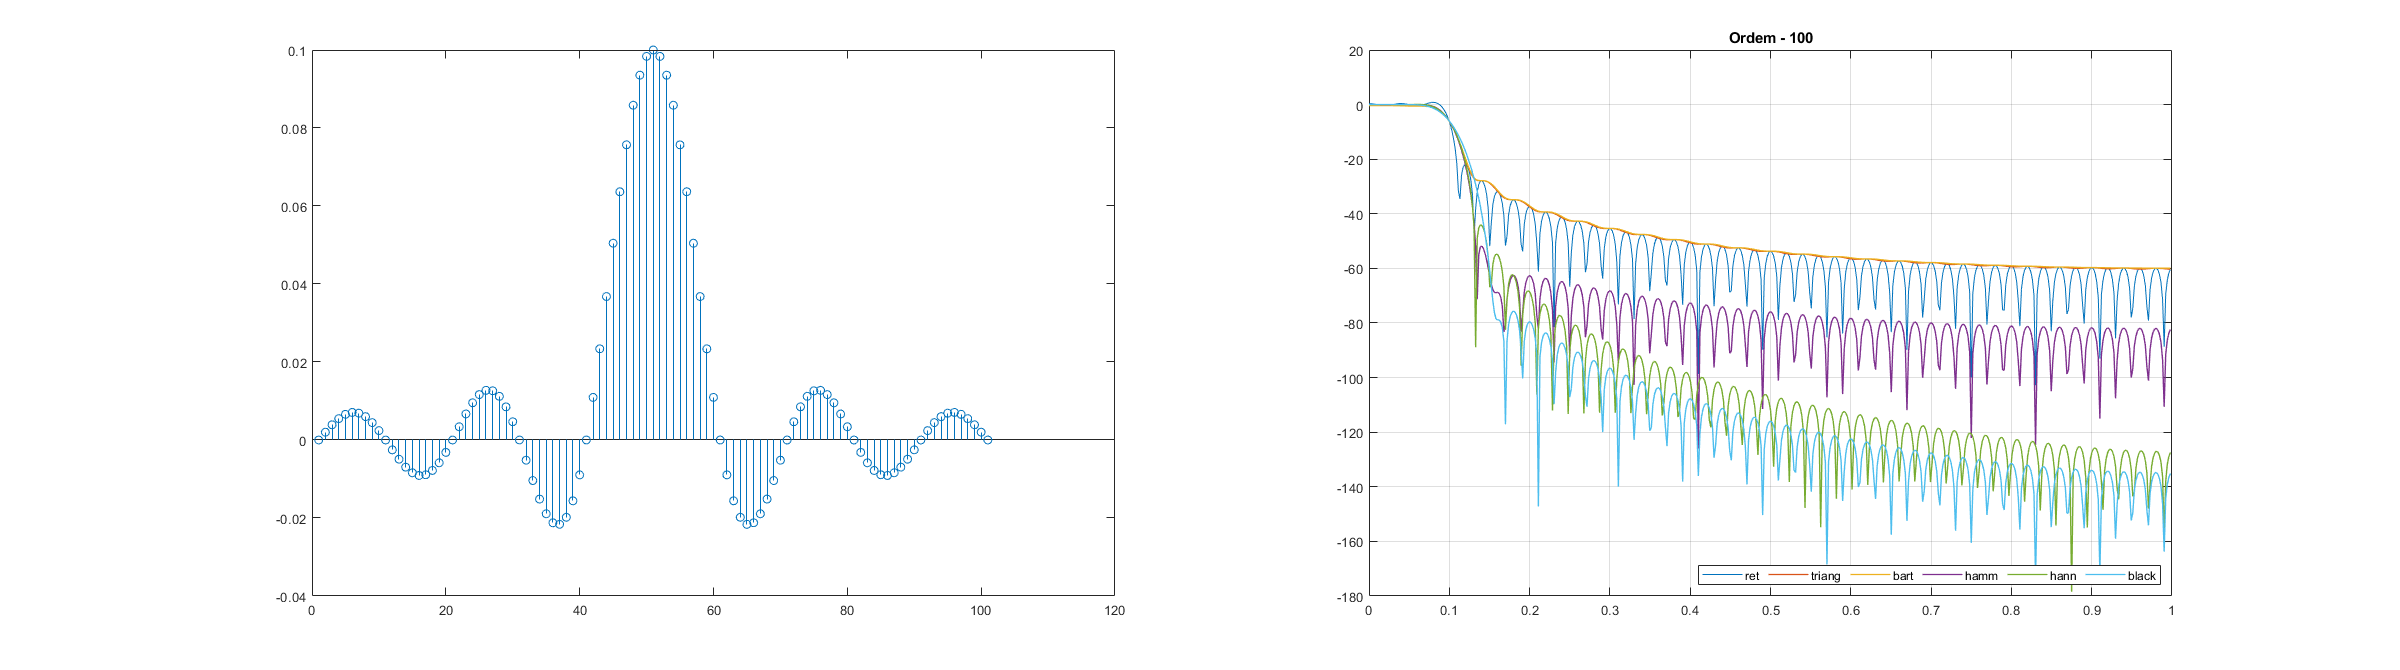

%a passa baixas
  Fs=20000;
  
M=[20 50 100];
wc1=(2*pi*1000)/(Fs);
h0=wc1/pi;

for a=1:3
figure('Position',[100 100 2400 670])
jnl=0;

n=1:M(a)/2;
jnl=[triang(M(a)+1)'; bartlett(M(a)+1)'; hamming(M(a)+1)'; hanning(M(a)+1)';blackman(M(a)+1)'];
haux=((sin(wc1.*n))./(pi.*n));
h=[fliplr(haux) h0 haux];
subplot(1,2,1);
stem(h);
[H1,w]=freqz(h);
subplot(1,2,2);
plot(w/pi, 20*log10(abs(H1)), 'LineWidth', 0.7); hold on; grid on;
for i=1:5
hold on;
haux=((sin(wc1.*n))./(pi.*n));
h=[fliplr(haux) h0 haux];
subplot(1,2,1);
stem(h);
si=h.*jnl(i,:);
[H1,w]=freqz(si);
subplot(1,2,2);
plot(w/pi, 20*log10(abs(H1)), 'LineWidth',1 ); hold on; grid on;

end
subplot(1,2,2);
legend({'ret','triang','bart','hamm','hann','black'},'Location','southeast','Orientation','horizontal')
title(sprintf('Ordem - %d', M(a)));
%legend({'ret','triang','bart'},'Location','southeast','Orientation','horizontal')
end 


%tambem colocar do impulso

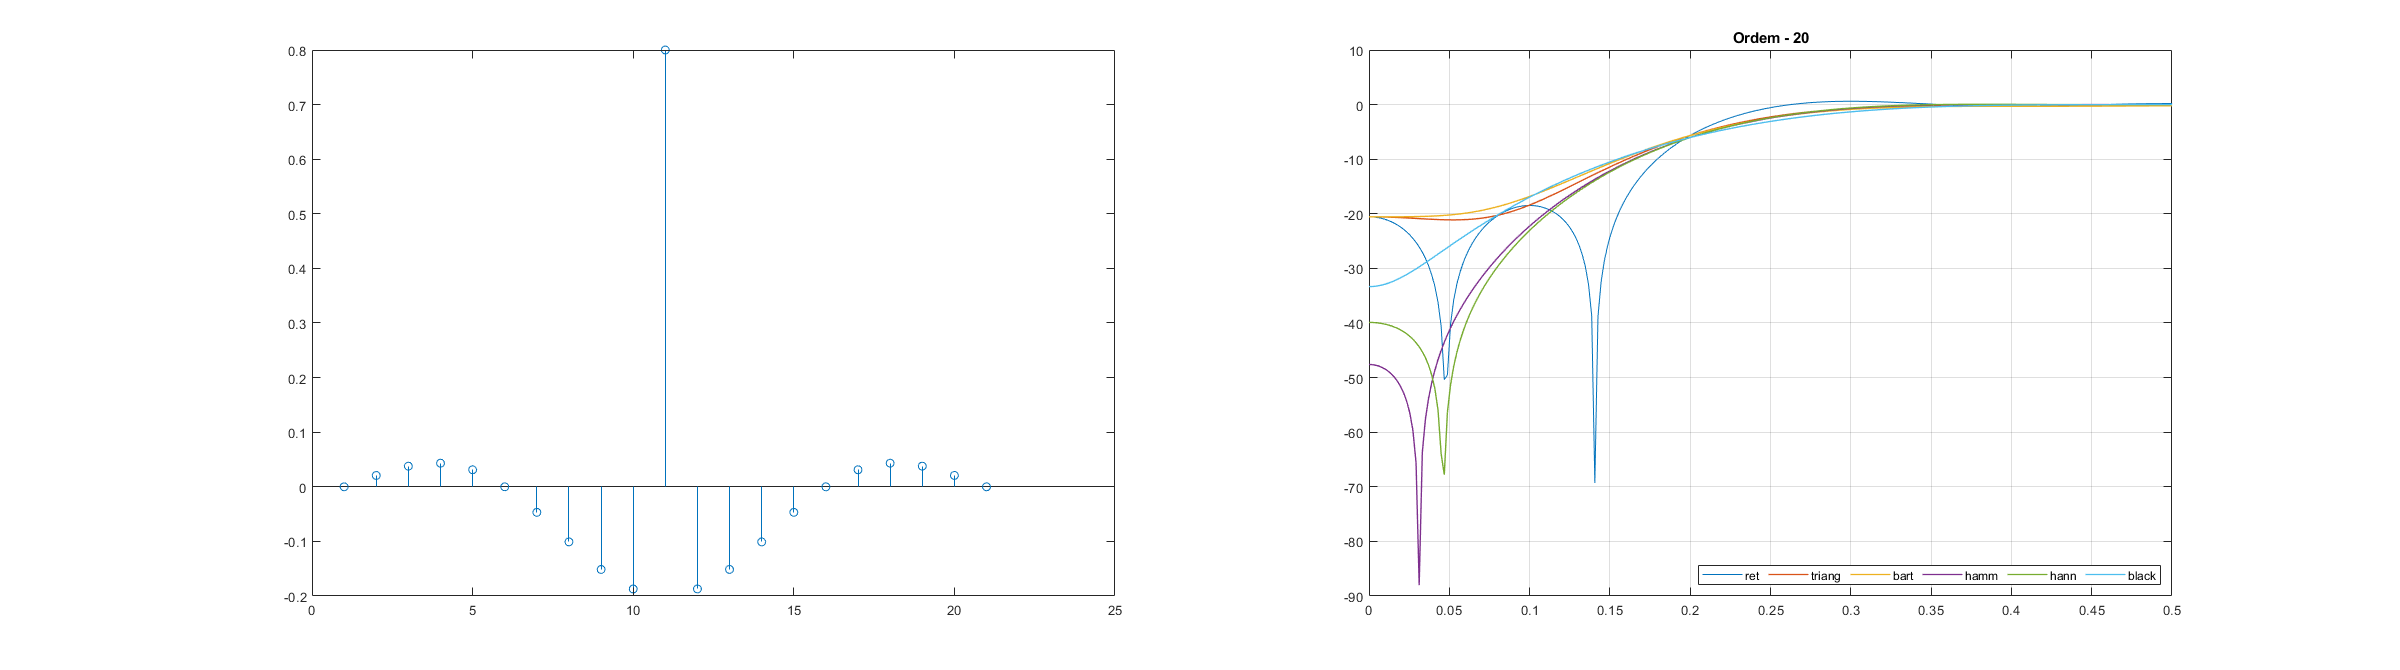

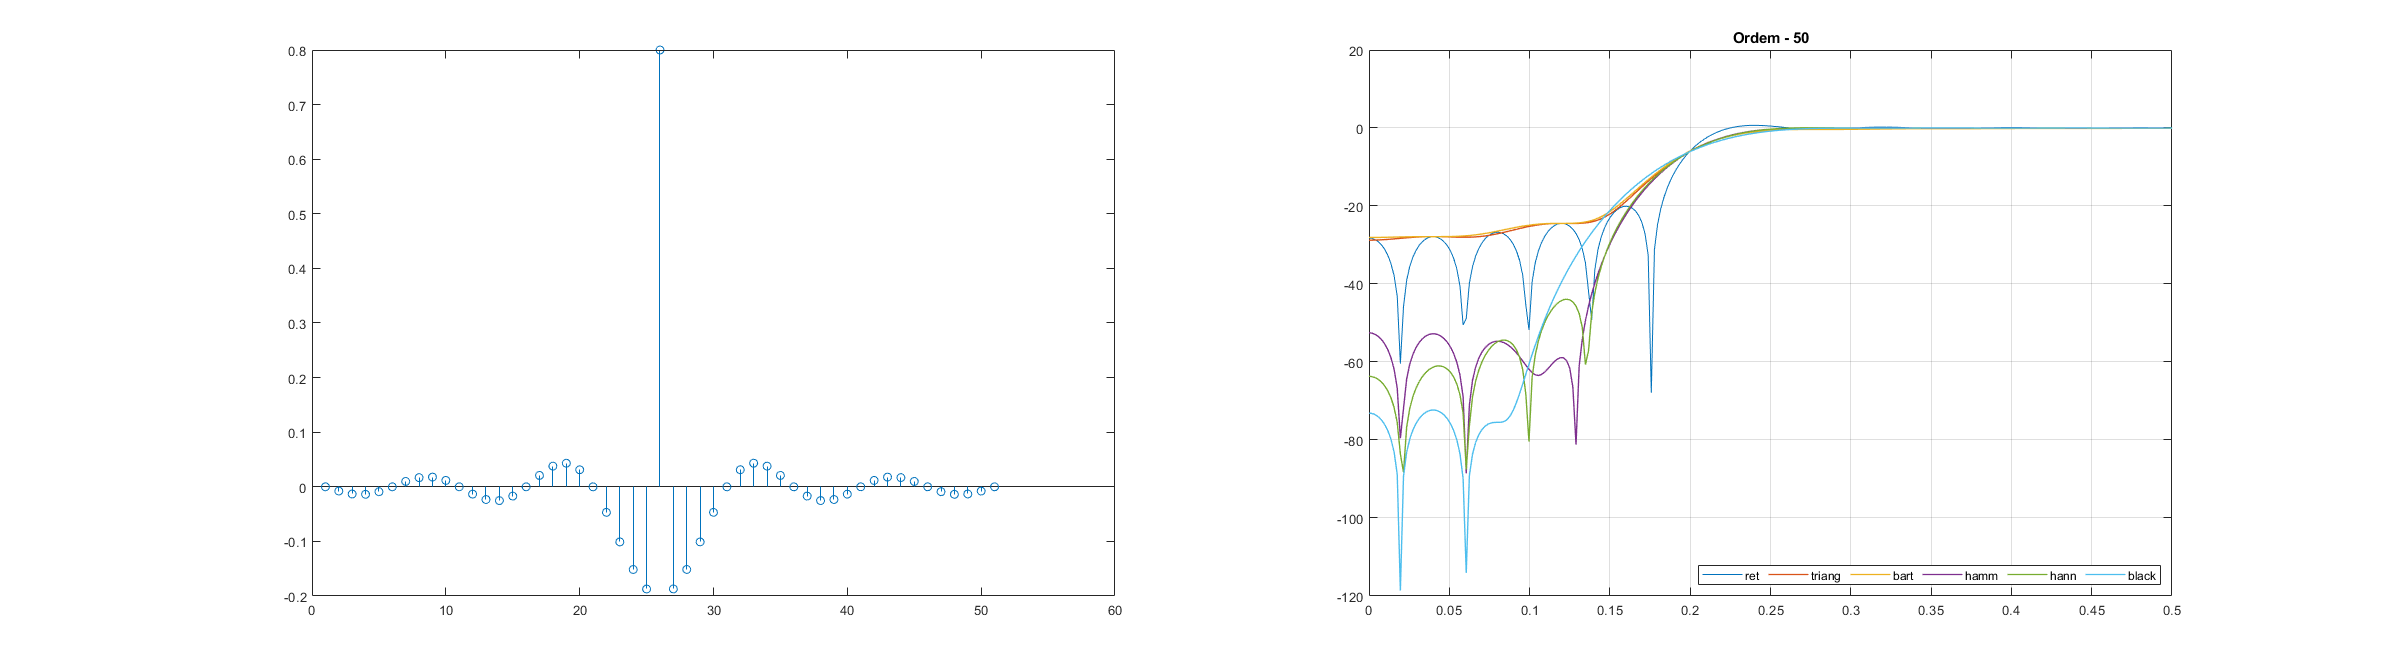

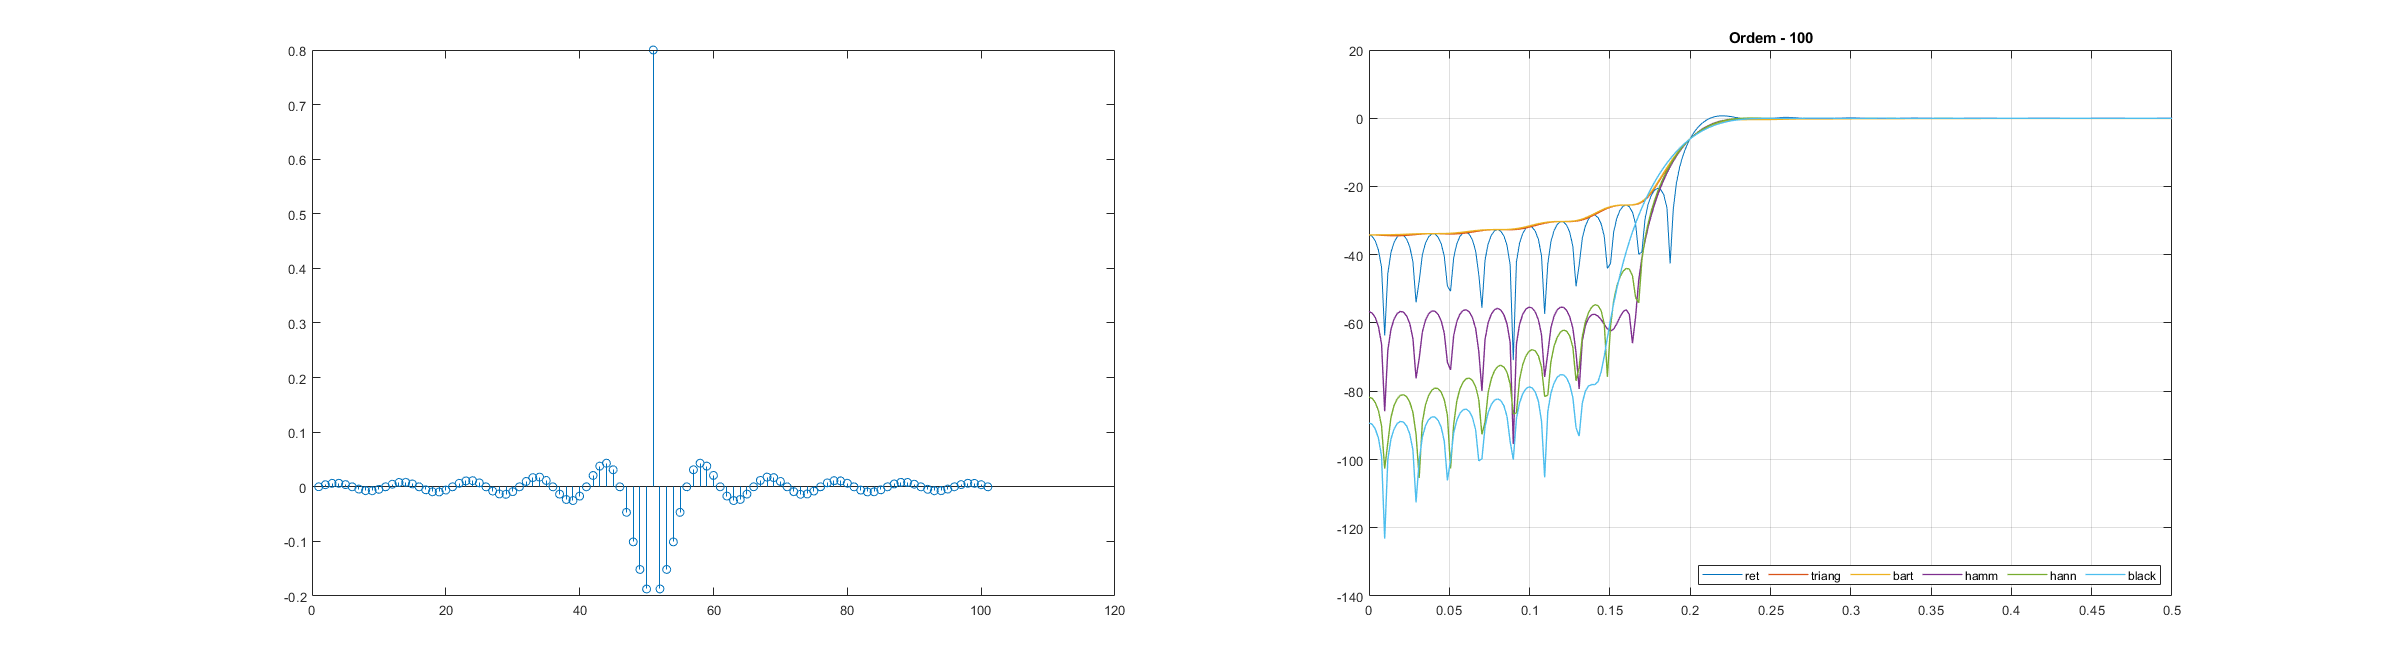

%a passa alta
  Fs=20000;
  
M=[20 50 100];
wc1=(2*pi*2000)/(Fs);
h0=1-wc1/pi;
for a=1:3
figure('Position',[100 100 2400 670])
jnl=0;
n=1:M(a)/2;
jnl=[triang(M(a)+1)'; bartlett(M(a)+1)'; hamming(M(a)+1)'; hanning(M(a)+1)';blackman(M(a)+1)'];
haux=(-(sin(wc1.*n))./(pi.*n));
h=[fliplr(haux) h0 haux];
subplot(1,2,1);
stem(h);
[H1,w]=freqz(h);
subplot(1,2,2);
plot(w/pi, 20*log10(abs(H1)), 'LineWidth', 0.7); hold on; grid on;
for i=1:5
hold on;
haux=(-(sin(wc1.*n))./(pi.*n));
h=[fliplr(haux) h0 haux];
subplot(1,2,1);
stem(h);
si=h.*jnl(i,:);
[H1,w]=freqz(si);
subplot(1,2,2);
plot(w/pi, 20*log10(abs(H1)), 'LineWidth',1 ); hold on; grid on;
end
xlim([0 0.5])
 title(sprintf('Ordem - %d', M(a)));
legend({'ret','triang','bart','hamm','hann','black'},'Location','southeast','Orientation','horizontal')
%legend({'ret','triang','bart'},'Location','southeast','Orientation','horizontal')
end 

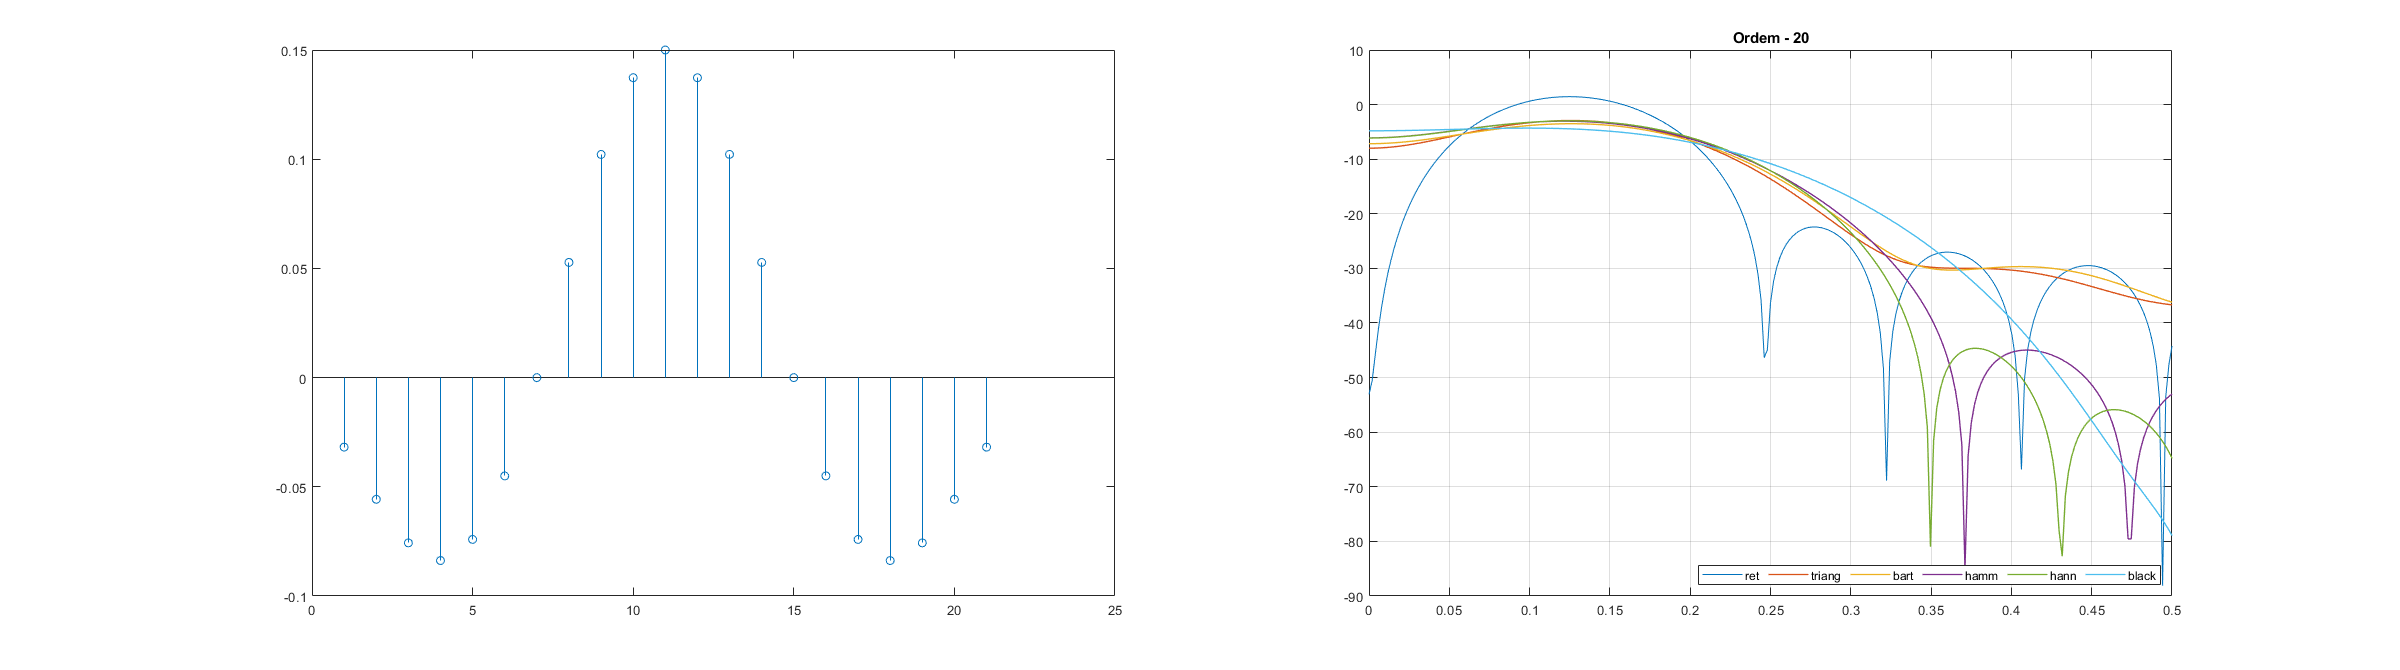

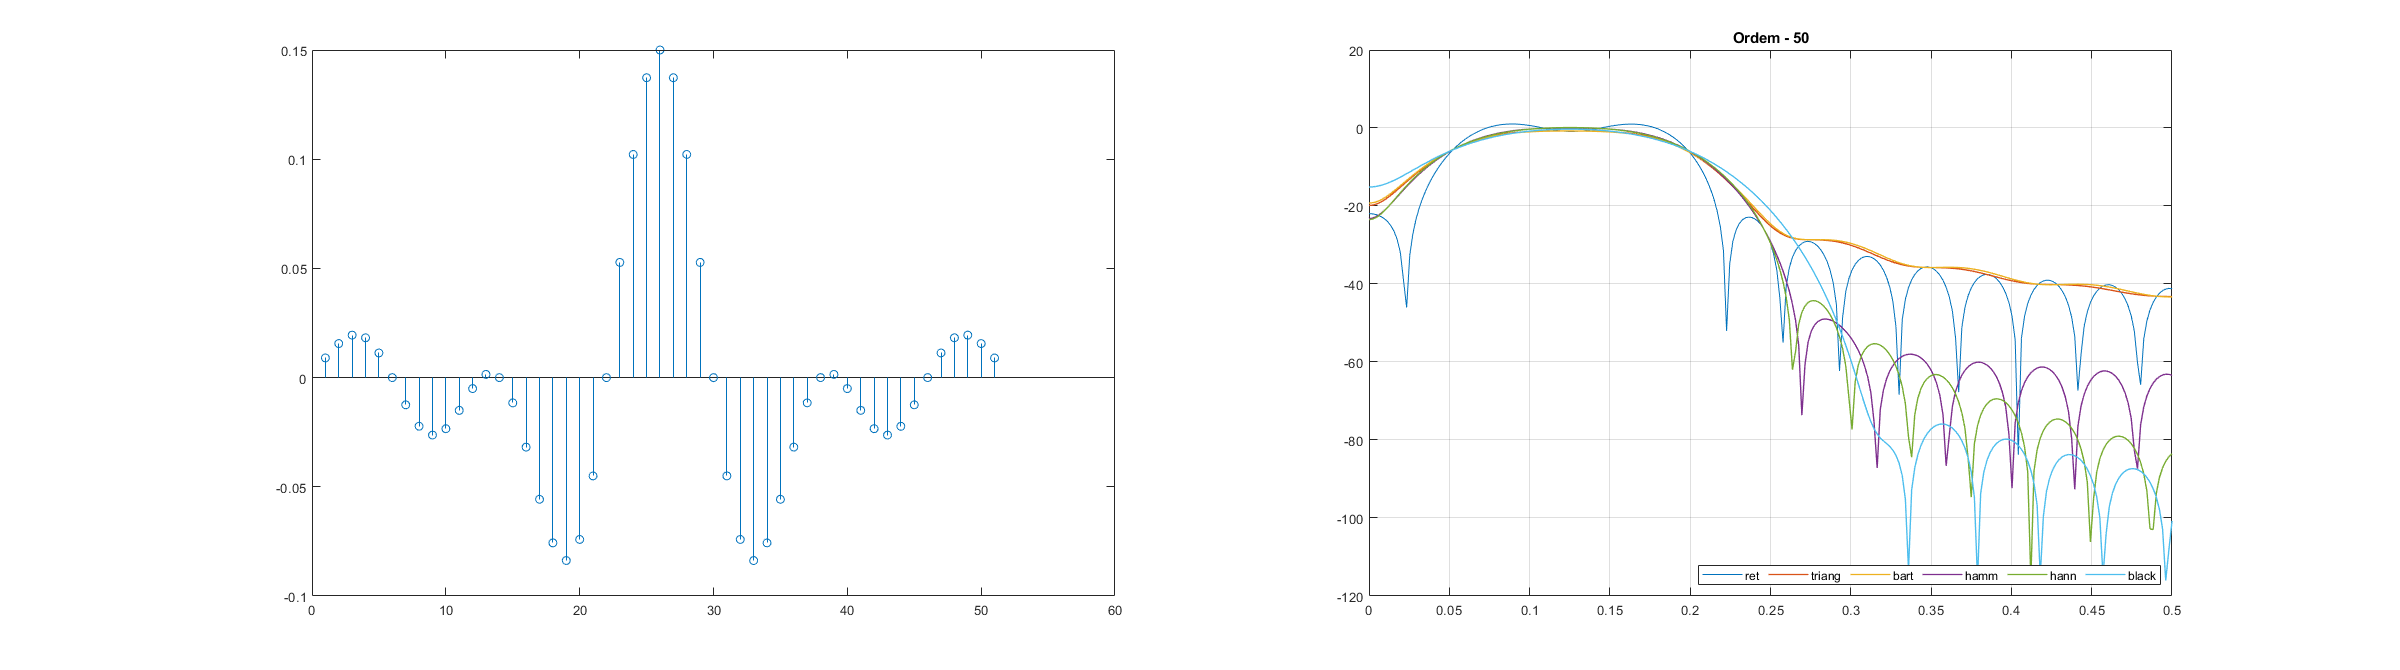

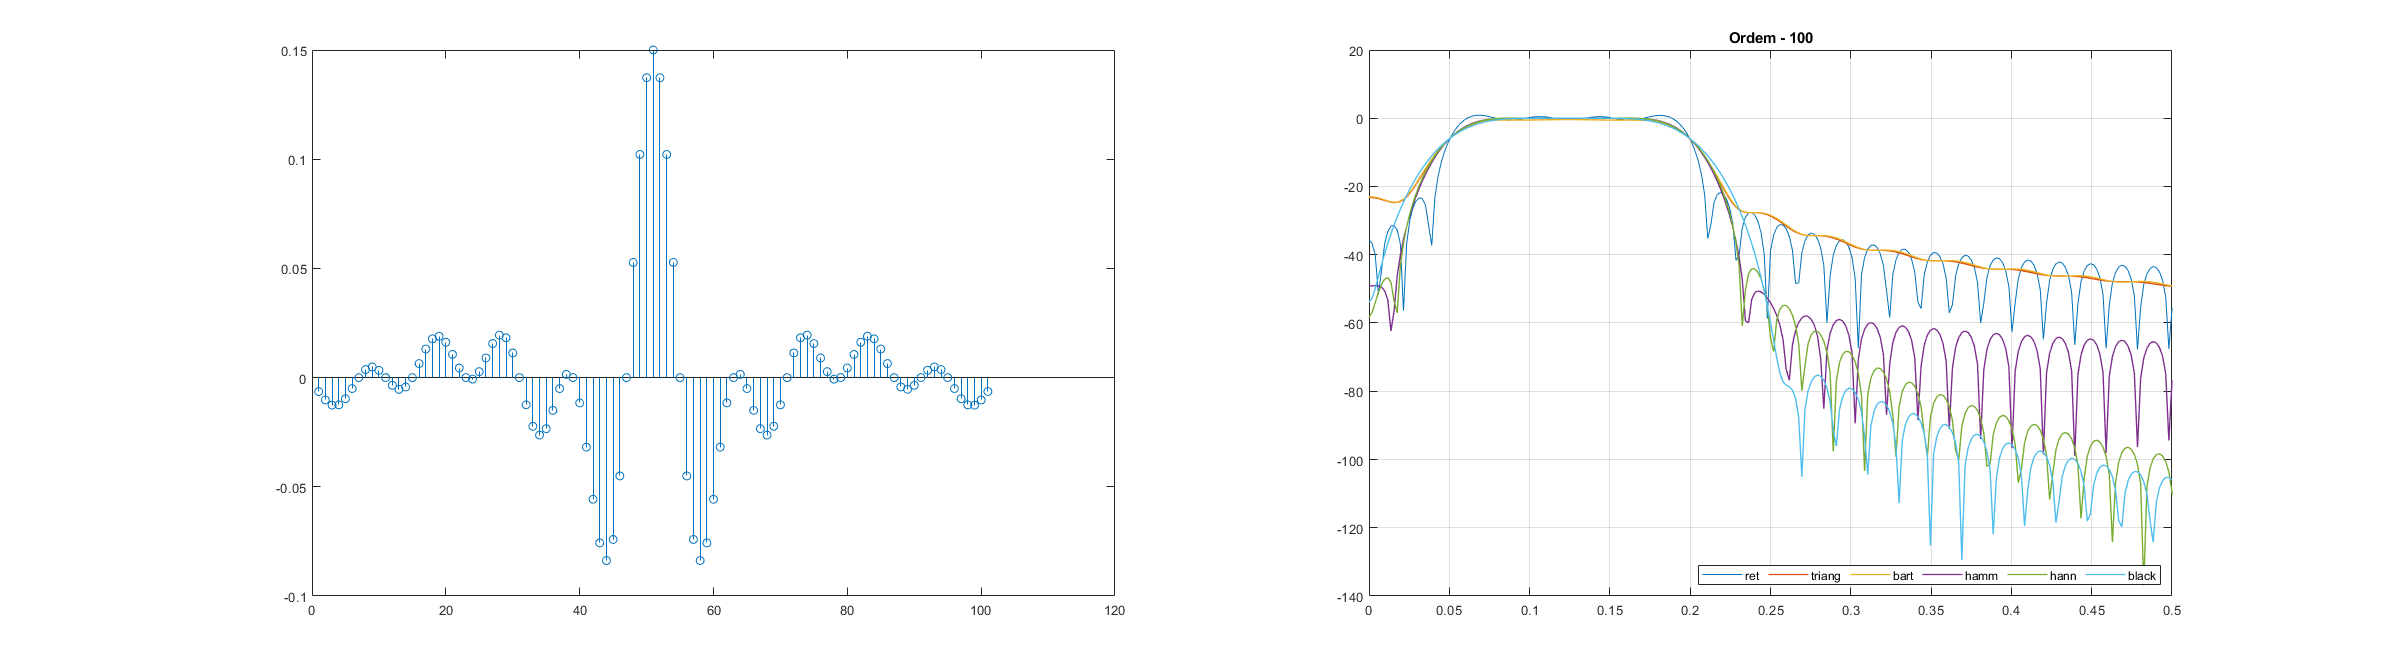

%a passa faixa
  Fs=20000;
  
M=[20 50 100];
wc1=(2*pi*500)/(Fs);
wc2=(2*pi*2000)/(Fs);
h0=(wc2-wc1)/pi;
for a=1:3
figure('Position',[100 100 2400 670])
jnl=0;
n=1:M(a)/2;
jnl=[triang(M(a)+1)'; bartlett(M(a)+1)'; hamming(M(a)+1)'; hanning(M(a)+1)';blackman(M(a)+1)'];
haux=(sin(wc2.*n)-sin(wc1.*n))./(pi.*n);
h=[fliplr(haux) h0 haux];
subplot(1,2,1);
stem(h);
[H1,w]=freqz(h);
subplot(1,2,2);
plot(w/pi, 20*log10(abs(H1)), 'LineWidth', 0.7); hold on; grid on;
for i=1:5
hold on;
haux=(sin(wc2.*n)-sin(wc1.*n))./(pi.*n);
h=[fliplr(haux) h0 haux];
subplot(1,2,1);
stem(h);
si=h.*jnl(i,:);
[H1,w]=freqz(si);
subplot(1,2,2);
plot(w/pi, 20*log10(abs(H1)), 'LineWidth',1 ); hold on; grid on;
end
xlim([0 0.5])
 title(sprintf('Ordem - %d', M(a)));
legend({'ret','triang','bart','hamm','hann','black'},'Location','southeast','Orientation','horizontal')
%legend({'ret','triang','bart'},'Location','southeast','Orientation','horizontal')
end 

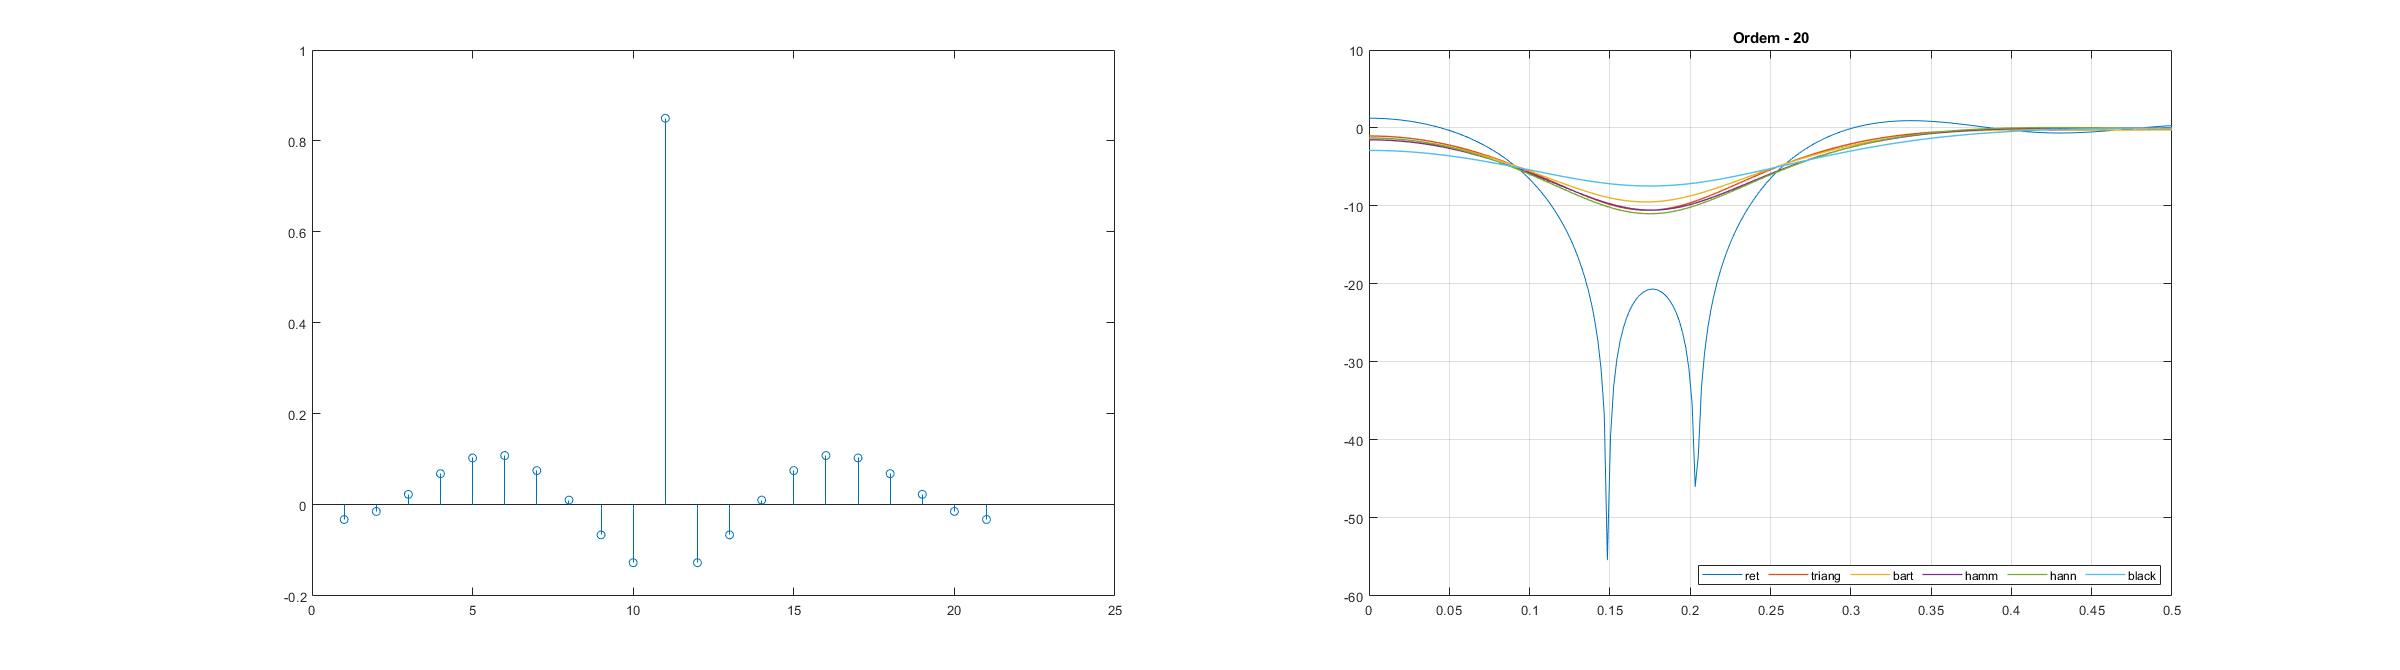

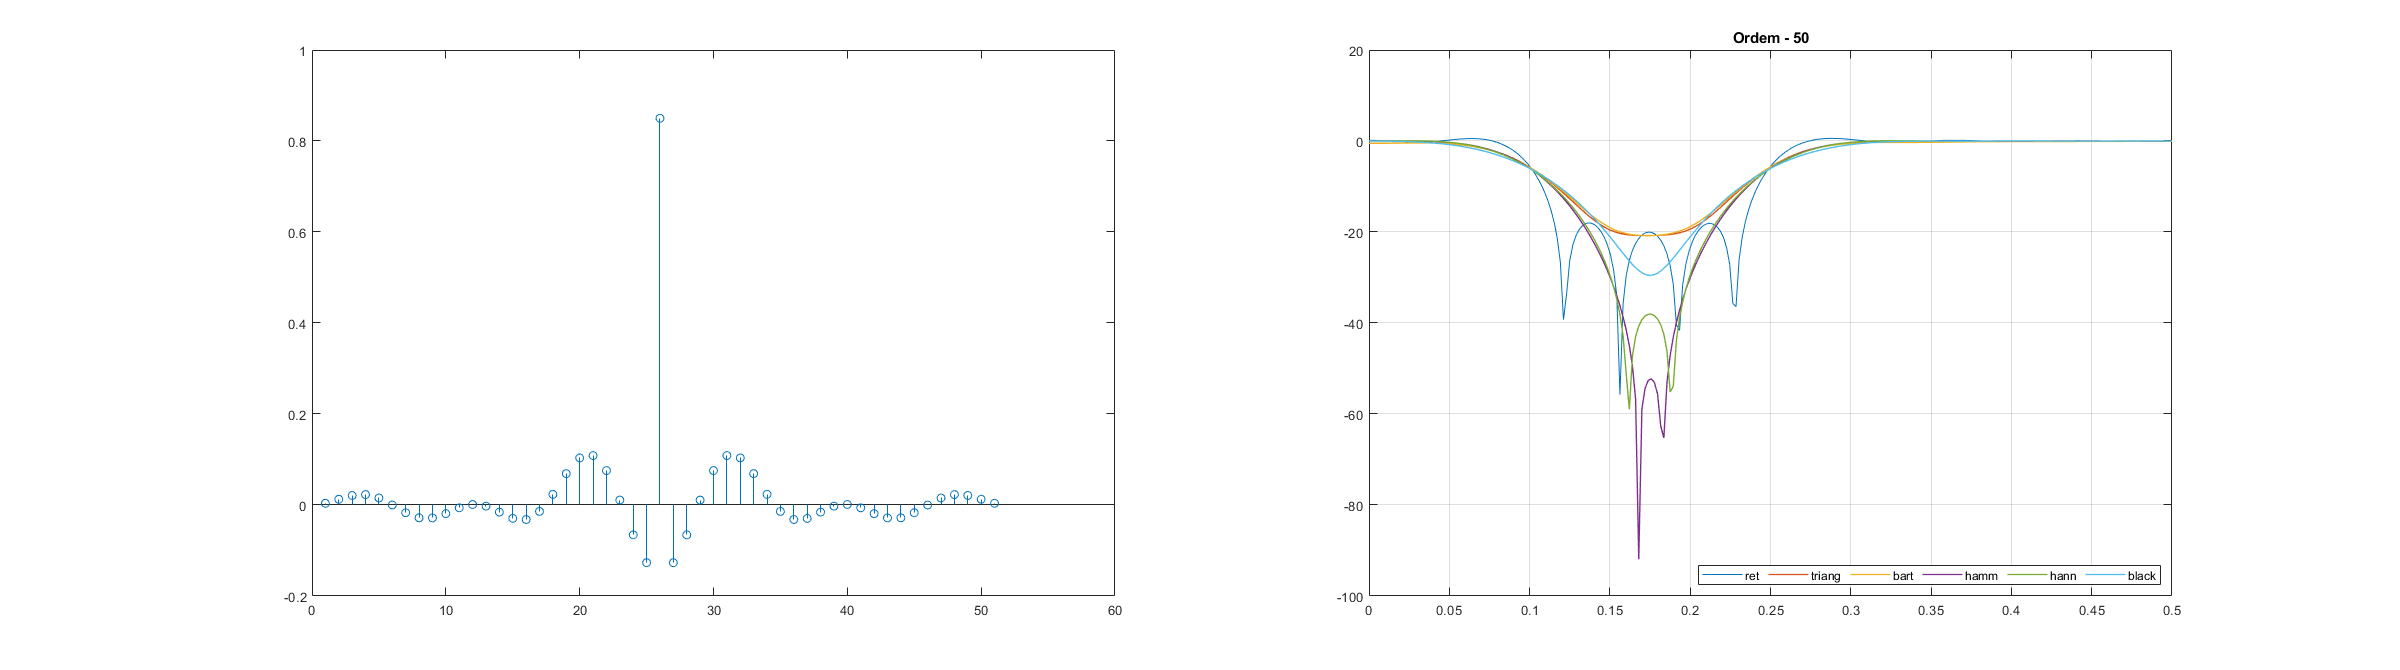

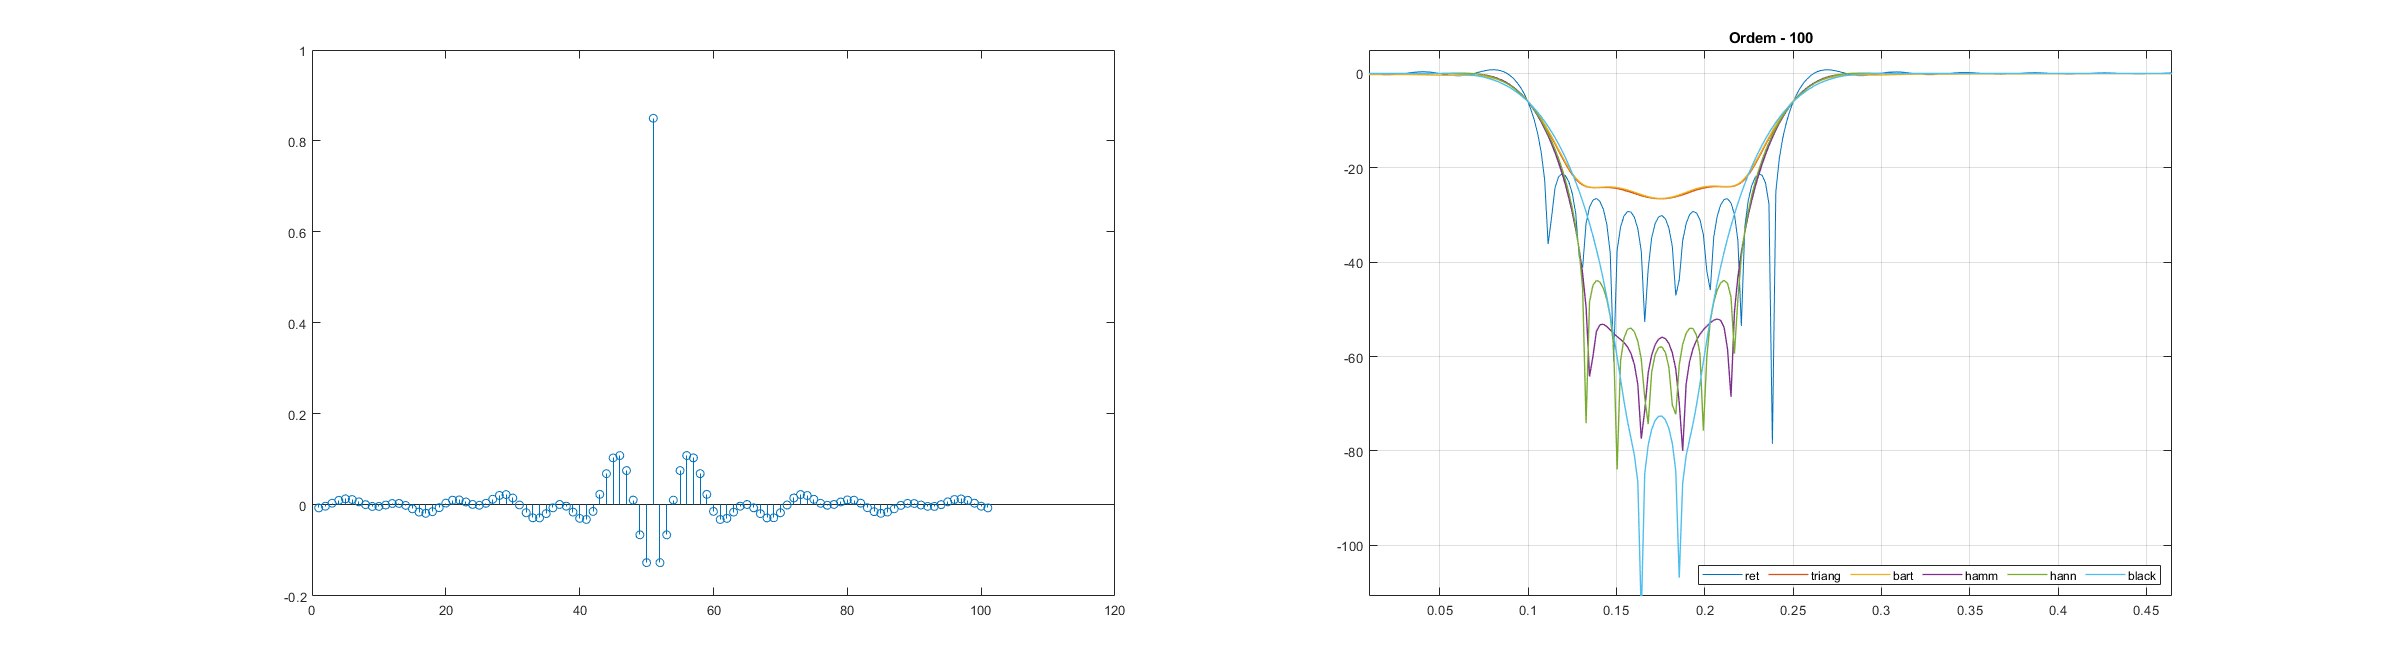

%a reijeita faixa
  Fs=20000;
  
M=[20 50 100];
wc1=(2*pi*1000)/(Fs);
wc2=(2*pi*2500)/(Fs);
h0=1-(wc2-wc1)/pi;
for a=1:3
figure('Position',[100 100 2400 670])
jnl=0;
n=1:M(a)/2;
jnl=[triang(M(a)+1)'; bartlett(M(a)+1)'; hamming(M(a)+1)'; hanning(M(a)+1)';blackman(M(a)+1)'];
haux=(sin(wc1.*n)-sin(wc2.*n))./(pi.*n);
h=[fliplr(haux) h0 haux];
subplot(1,2,1);
stem(h);
[H1,w]=freqz(h);
subplot(1,2,2);
plot(w/pi, 20*log10(abs(H1)), 'LineWidth', 0.7); hold on; grid on;
for i=1:5
hold on;
haux=(sin(wc1.*n)-sin(wc2.*n))./(pi.*n);
h=[fliplr(haux) h0 haux];
subplot(1,2,1);
stem(h);
si=h.*jnl(i,:);
[H1,w]=freqz(si);
subplot(1,2,2);
plot(w/pi, 20*log10(abs(H1)), 'LineWidth',1 ); hold on; grid on;
end
xlim([0 0.5])
 title(sprintf('Ordem - %d', M(a)));
legend({'ret','triang','bart','hamm','hann','black'},'Location','southeast','Orientation','horizontal')
%legend({'ret','triang','bart'},'Location','southeast','Orientation','horizontal')
end 

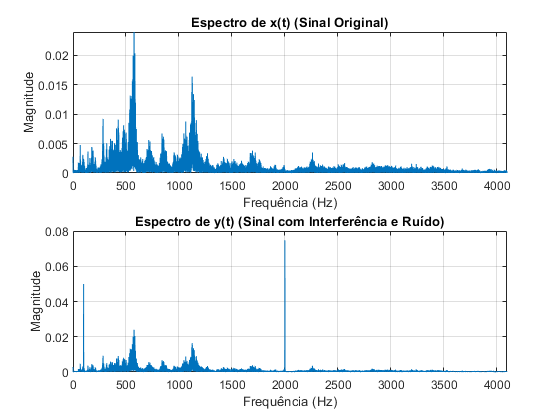

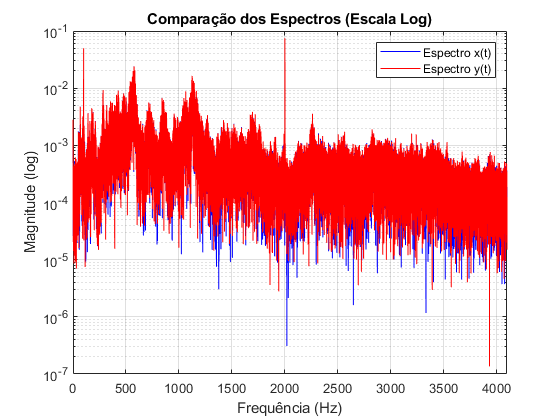

load handel.mat
x=y; clear y;
n=(10^-2)*randn(size(x));
N=length(x);
t = (0:N-1)' / Fs;
yn=x+0.05.*cos(200*pi*t)+0.075.*sin(4000*pi*t)+n;
[f_x, mag_x] = calcular_espectro(x, Fs);
[f_y, mag_y] = calcular_espectro(yn, Fs);
figure;
subplot(2,1, 1); % Organiza os plots

% Plot do espectro de x(t)

plot(f_x, mag_x);
title('Espectro de x(t) (Sinal Original)');
xlabel('Frequência (Hz)');
ylabel('Magnitude');
grid on;
xlim([0 Fs/2]); % Mostrar de 0 até a frequência de Nyquist
subplot(2,1, 2);
% Plot do espectro de y(t)

plot(f_y, mag_y);
title('Espectro de y(t) (Sinal com Interferência e Ruído)');
xlabel('Frequência (Hz)');
ylabel('Magnitude');
grid on;
xlim([0 Fs/2]);

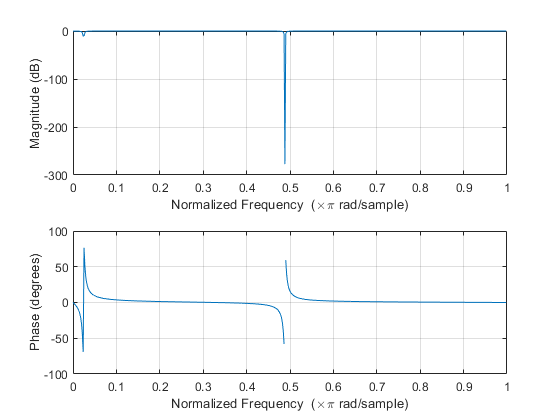

r=0.99;%muito proximo de 1 se não vai acabar ocorrendo uma supresão de frequencias não desejadas
w1=2*pi*2000/(Fs);
w2=2*pi*100/(Fs);
m_11=-2*r*cos(w1);
    m_21=r^2;

Num1=[1 (m_11/sqrt(m_21)) 1];
Den1= [1 m_11 m_21];
m_12=-2*r*cos(w2);
    m_22=r^2;

Num2=[1 (m_12/sqrt(m_22)) 1];
Den2= [1 m_12 m_22];

nf=conv(Num1,Num2);
df=conv(Den1,Den2);
freqz(nf,df);

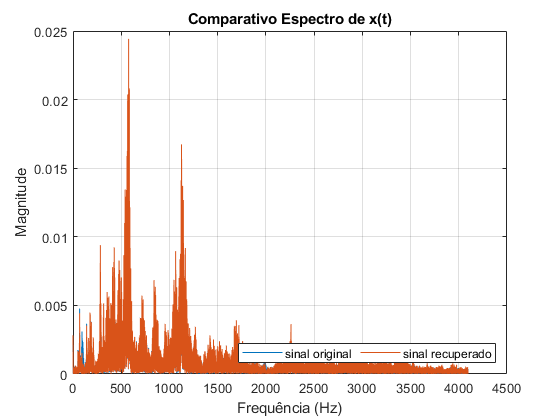

f_rec=filter(nf,df,yn);
[f_x, mag_x] = calcular_espectro(x, Fs);
[f_y, mag_y] = calcular_espectro(f_rec, Fs);

plot(f_x, mag_x);
hold on;
plot(f_y, mag_y);

title(' Comparativo Espectro de x(t) ');
xlabel('Frequência (Hz)');
ylabel('Magnitude');
legend({'sinal original','sinal recuperado'},'Location','southeast','Orientation','horizontal')
grid on;